clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
output_path = fullfile(base_output_path, 'longitudinal_dPCA');

if ~exist(output_path, 'dir')
    mkdir(output_path);
    fprintf('Created new output directory: %s\n', output_path);
end

conditions = {'BLA','BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load
time_ms_eeg = [];

## 1.1 Load and import file as EEGLAB matrix

data_all_conds = struct();

% Loop through the conditions
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Load excel file paths for P2 and P3 ONCE per condition
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path, 'Indexes for P2.xlsx');
        epoch_trials_p2_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p2_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path, 'Indexes for P3.xlsx');
        epoch_trials_p3_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p3_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
    end

    % --- NEW: Loop through ALL subjects for this condition ---
    for s = 1:length(names_sorted)
        file_to_load = names_sorted{s}; 
        fprintf('Loading Subj %d/%d (%s) for condition: %s\n', s, length(names_sorted), file_to_load, condition);
        
        EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
        if isempty(fs), fs = EEG.srate; end
        
        if isempty(time_ms_eeg)
            time_ms_eeg = linspace(0, 3.5 , size(EEG.data, 2)); 
        end
        
        % Extract data and store in a cell array to avoid dimension mismatch
        if ismember(condition, {'BLA', 'BLT', 'P1'})
            epoch_trials = 1:2:EEG.trials;
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials);
            
        elseif strcmp(condition, 'P2')
            epoch_trials_p2 = 1:2:EEG.trials;     
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials_p2);
            data_all_conds.P2_500{s}      = EEG.data(:, :, epoch_trials_p2_500ms);
            data_all_conds.P2_2000{s}     = EEG.data(:, :, epoch_trials_p2_2000ms);
            
        elseif strcmp(condition, 'P3')
            epoch_trials_p3 = 1:2:EEG.trials;
            data_all_conds.(condition){s}   = EEG.data(:, :, epoch_trials_p3);
            data_all_conds.P3_500{s}        = EEG.data(:, :, epoch_trials_p3_500ms);
            data_all_conds.P3_missing{s}    = EEG.data(:, :, epoch_trials_p3_missing);
        end
    end
end

Loading Subj 1/14 (binepochs filtered ICArej BLAAvgBOS10.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLAAvgBOS11.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLAAvgBOS12.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLAAvgBOS13.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLAAvgBOS15.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLAAvgBOS16.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLAAvgBOS17.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLAAvgBOS2.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLAAvgBOS3.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLAAvgBOS5.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLAAvgBOS6.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLAAvgBOS7.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLAAvgBOS8.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLAAvgBOS9.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej BLTAvgBOS10.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLTAvgBOS11.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLTAvgBOS12.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLTAvgBOS13.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLTAvgBOS15.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLTAvgBOS16.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLTAvgBOS17.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLTAvgBOS2.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLTAvgBOS3.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLTAvgBOS5.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLTAvgBOS6.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLTAvgBOS7.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLTAvgBOS8.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLTAvgBOS9.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P1AvgBOS10.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P1AvgBOS11.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P1AvgBOS12.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P1AvgBOS13.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P1AvgBOS15.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P1AvgBOS16.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P1AvgBOS17.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P1AvgBOS2.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P1AvgBOS3.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P1AvgBOS5.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P1AvgBOS6.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P1AvgBOS7.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P1AvgBOS8.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P1AvgBOS9.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P2AvgBOS10.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P2AvgBOS11.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P2AvgBOS12.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P2AvgBOS13.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P2AvgBOS15.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P2AvgBOS16.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P2AvgBOS17.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P2AvgBOS2.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P2AvgBOS3.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P2AvgBOS5.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P2AvgBOS6.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P2AvgBOS7.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P2AvgBOS8.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P2AvgBOS9.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P3AvgBOS10.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P3AvgBOS11.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P3AvgBOS12.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P3AvgBOS13.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P3AvgBOS15.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P3AvgBOS16.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P3AvgBOS17.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P3AvgBOS2.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P3AvgBOS3.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P3AvgBOS5.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P3AvgBOS6.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P3AvgBOS7.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P3AvgBOS8.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P3AvgBOS9.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## 1.2 Visualizing the conditions raw data

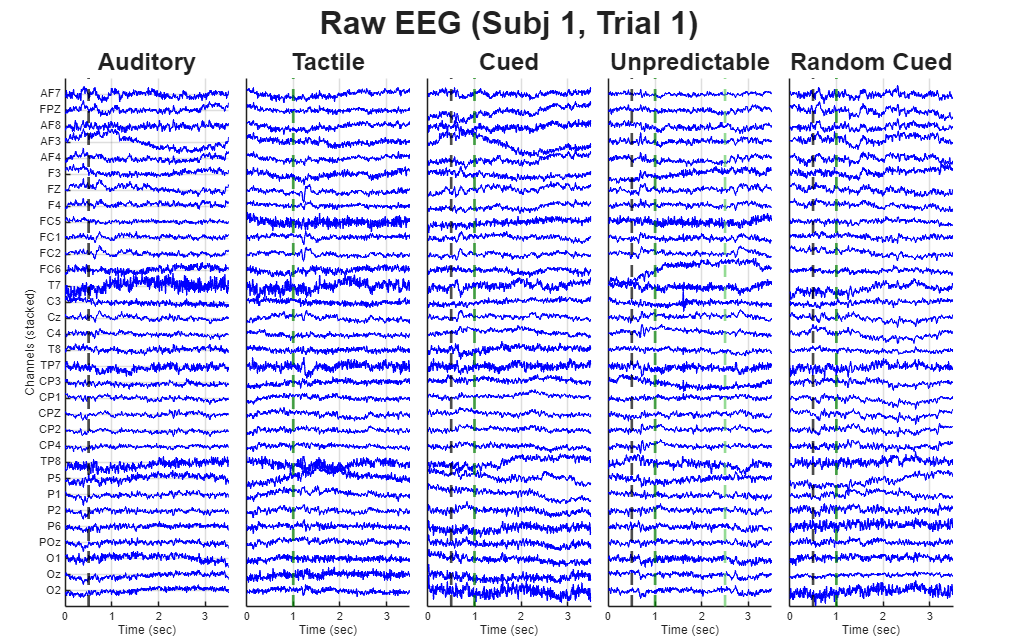

%% Visualizing Specific Trial for a Specific Subject
target_trial = 1; 
target_subject = 1; 

if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    display_channels_str = cellstr(num2str((1:size(data_all_conds.BLT{1}, 1))')); 
end

num_channels_plot = length(display_channels_str);
plot_conds = fieldnames(data_all_conds);
num_conds = length(conditions); % Just plotting the base conditions for now

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, sprintf('Raw EEG (Subj %d, Trial %d)', target_subject, target_trial), 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;

for c = 1:num_conds
    cond_name = conditions{c};
    
    % Access the cell for the subject, then slice the 3rd dimension for the trial
    data_to_plot = data_all_conds.(cond_name){target_subject}(:, :, target_trial);
    
    nexttile;
    hold on
    for ch = 1:num_channels_plot
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
    end
    
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]);
    end
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

disp('Calculating averages across trials and subjects...');

Calculating averages across trials and subjects...



cond_names = fieldnames(data_all_conds);
data_subj_avg = struct();
data_grand_avg = struct();
data_grand_std = struct();

for i = 1:length(cond_names)
    c_name = cond_names{i};
    num_subjects = length(data_all_conds.(c_name));
    
    % 1. Average across trials for EACH subject
    % Preallocate [Channels x Time x Subjects]
    subj_avg_matrix = zeros(num_ch, length(time_ms_eeg), num_subjects);
    
    for s = 1:num_subjects
        % Average across dim 3 (trials)
        subj_avg_matrix(:,:,s) = mean(data_all_conds.(c_name){s}, 3, 'omitnan');
    end
    data_subj_avg.(c_name) = subj_avg_matrix;
    
    % 2. Average across subjects (Grand Average)
    data_grand_avg.(c_name) = mean(subj_avg_matrix, 3, 'omitnan');
    
    % 3. Standard Deviation across subjects (for shaded error bars)
    data_grand_std.(c_name) = std(subj_avg_matrix, 0, 3, 'omitnan');
end

%% Visualizing Grand Average with STD Shading
channels_to_plot = {'AF3', 'F3', 'FZ', 'FC5', 'FC1',  'T7', 'C3', 'Cz', 'C4', 'T8', 'TP7', 'CP3', 'CP1',  'P5', 'P1', 'O1', 'Oz', 'O2'};

[~, chan_idx] = ismember(channels_to_plot, display_channels_str);
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
num_conds = length(conditions); 


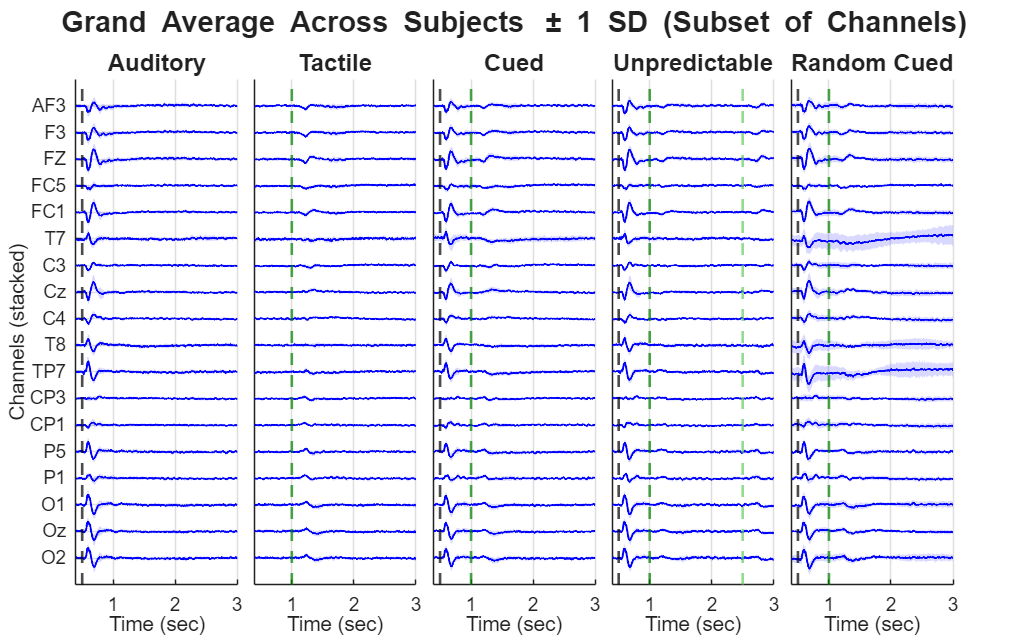

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Grand Average Across Subjects \pm 1 SD (Subset of Channels)', 'FontSize', 22, 'FontWeight', 'bold');

offset = 15; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;
time_fill = [time_ms_eeg, fliplr(time_ms_eeg)]; % X-axis for shading

for c = 1:num_conds
    cond_name = conditions{c};
    
    nexttile;
    hold on
    
    for ch = 1:num_channels_plot
        actual_ch = chan_idx(ch);
        y_shift = (num_channels_plot - ch) * offset;
        
        % Extract mean and std for this specific channel
        mu = data_grand_avg.(cond_name)(actual_ch, :) + y_shift;
        sigma = data_grand_std.(cond_name)(actual_ch, :);
        
        % Create boundaries for the shaded standard deviation
        y_bound = [mu + sigma, fliplr(mu - sigma)];
        
        % Plot Shaded STD Area first (so it sits behind the line)
        fill(time_fill, y_bound, 'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        
        % Plot Mean Line
        plot(time_ms_eeg, mu, 'b', 'LineWidth', 1.5);
    end
    
    % Add Vertical Event Lines
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([0.4, 3]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); 
    end
    
    set(gca,'FontSize',14);
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

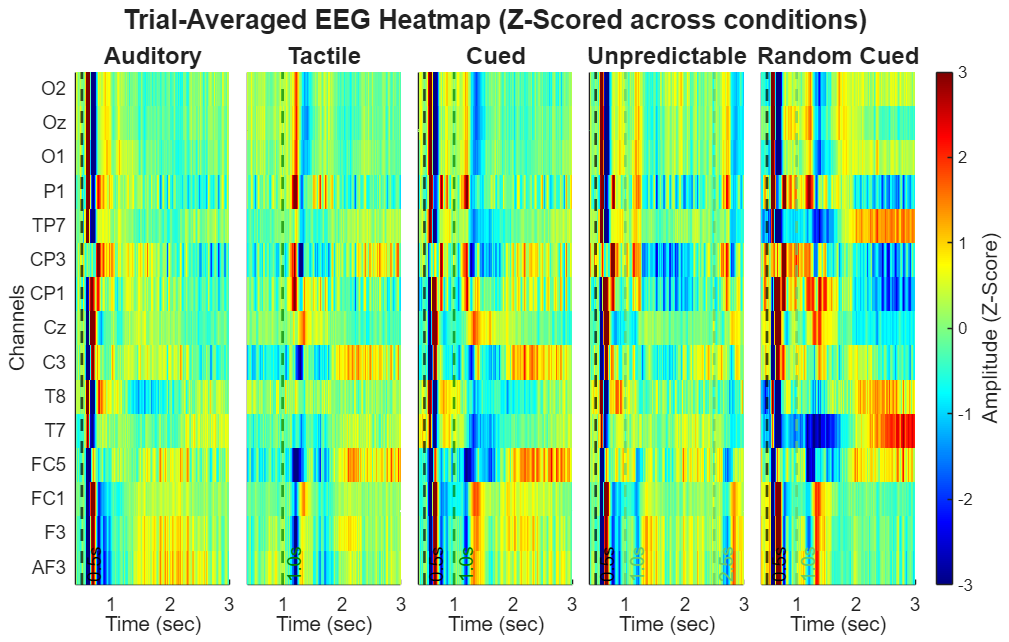

% 1. Define the specific channels you want to plot
channels_to_plot = {'AF3', 'F3', 'Fz', 'FC1', 'FC5', 'T7', 'T8', 'C3', 'Cz', 'CP1', 'CP3', 'TP7', 'P1', 'O1', 'Oz', 'O2'};

% Safely extract all 32 channel labels 
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    all_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace
    all_channels_str = cellstr(num2str((1:size(data_grand_avg.BLT, 1))')); 
end

% 2. Find the indices of the requested channels within the full list
[~, chan_idx] = ismember(channels_to_plot, all_channels_str);

% Safety check: remove any channels from the list that weren't found
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);

% Define your observed conditions (ensure 'BLA' is included if you use it in the loop)
conditions = {'BLA', 'BLT', 'P1', 'P2', 'P3'};
num_conds = length(conditions); 

% --- NEW: Z-score across all conditions per channel ---
% Concatenate all condition data to compute global mean and std per channel
concat_data = [];
for c = 1:num_conds
    cond_name = conditions{c};
    concat_data = [concat_data, data_grand_avg.(cond_name)];
end

% Calculate mean and std specifically for the selected channels
mu_chan = mean(concat_data(chan_idx, :), 2);
sigma_chan = std(concat_data(chan_idx, :), 0, 2);

% Prevent division by zero if a channel is completely flat
sigma_chan(sigma_chan == 0) = 1; 

% Set color limits to typical Z-score bounds (±3 standard deviations)
color_limits = [-3, 3]; 

% Widen the figure to comfortably fit side-by-side plots
figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Trial-Averaged EEG Heatmap (Z-Scored across conditions)', 'FontSize', 20, 'FontWeight', 'bold');

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Loop through all conditions to generate the tiles dynamically
for c = 1:num_conds
    cond_name = conditions{c};
    
    % --- Extract and Z-score the Data ---
    raw_data = data_grand_avg.(cond_name)(chan_idx, :);
    data_to_plot = (raw_data - mu_chan) ./ sigma_chan; % Z-score calculation
    
    nexttile;
    hold on;
    
    % 1. Plot the Heatmap
    imagesc(time_ms_eeg, 1:num_channels_plot, data_to_plot);
    
    % Apply the z-score color limits
    clim(color_limits); 
    
    % 2. Add Vertical Event Lines
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    else
        xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    if ismember(cond_name, 'P1')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    elseif strcmp(cond_name, 'P2')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    elseif strcmp(cond_name, 'P3')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    hold off;
    
    % Fit axes
    xlim([0.4, 3]); 
    ylim([0.5, num_channels_plot + 0.5]); 
    xlabel('Time (sec)'); 
    
    % Y-Axis formatting
    if c == 1
        ylabel('Channels');
        yticks(1:num_channels_plot);
        yticklabels(display_channels_str);
    else
        yticks([]); 
    end
    
    set(gca, 'YDir', 'normal', 'FontSize', 14);
    
    % Custom Titles
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    else
        plot_name = cond_name;
    end
    title(sprintf('%s', plot_name), 'FontSize', 18);
    
end

% Use a divergent colormap suitable for Z-scores
colormap('jet'); 
cb = colorbar;
cb.Layout.Tile = 'east'; 
cb.Label.String = 'Amplitude (Z-Score)';
cb.Label.FontSize = 16;

%% 2.0 Macro-Window PCA with 20ms Sliding Projections
disp('Performing Macro-Window PCA and projecting sliding windows...');

Performing Macro-Window PCA and projecting sliding windows...



pca_conditions = {'BLA', 'BLT', 'P1', 'P2_500', 'P2_2000', 'P2', 'P3_500', 'P3_missing', 'P3'};
num_comps = 4; 

% 1. Define Sliding Window Parameters for Projections
win_ms = 64;  % Small 64ms window for projections
step_ms = 20; % 20ms steps (no overlap)

if isempty(fs), fs = 512; end 
win_samples = round((win_ms / 1000) * fs);
step_samples = round((step_ms / 1000) * fs);

total_samples = length(time_ms_eeg);
win_starts = 1:step_samples:(total_samples - win_samples + 1);
n_windows = length(win_starts);

time_windows = zeros(1, n_windows);
for w = 1:n_windows
    idx = win_starts(w):(win_starts(w) + win_samples - 1);
    time_windows(w) = mean(time_ms_eeg(idx)); % Center time of the 20ms window
end

pca_static = struct();

for i = 1:length(pca_conditions)
    c_name = pca_conditions{i};
    X = data_grand_avg.(c_name); 
    
    % --- 1. Define the Macro-Window for this specific condition ---
    if strcmp(c_name, 'BLA')
        t_bounds = [0.4, 1.0];
    elseif strcmp(c_name, 'BLT')
        t_bounds = [0.9, 1.5];
    elseif strcmp(c_name, 'P2_2000')
        t_bounds = [0.4, 3.1]; % Extended window for delayed condition
    else
        t_bounds = [0.4, 1.5]; % P1, P2_500, P3 variants, etc.
    end
    
    % --- 2. Perform ONE PCA on the macro-window ---
    macro_idx = find(time_ms_eeg >= t_bounds(1) & time_ms_eeg <= t_bounds(2));
    X_macro = X(:, macro_idx);
    
    [coeff, ~, ~, ~, ~, mu] = pca(X_macro');
    coeff = coeff(:, 1:min(num_comps, size(coeff,2)));
    
    % Pre-allocate arrays for the 20ms sliding projections
    comp_time_matrix = zeros(num_comps, n_windows);
    var_time_matrix = zeros(num_comps, n_windows);
    
    % --- 3. Loop through the timeline and Project 20ms chunks ---
    for w = 1:n_windows
        idx = win_starts(w):(win_starts(w) + win_samples - 1);
        X_win = X(:, idx);
        
        % Project the 20ms data into the fixed PCA space
        % (Subtract the fixed macro-mean to keep math consistent)
        score_win = (X_win' - mu) * coeff;
        
        % Store the average amplitude for this 20ms block
        comp_time_matrix(:, w) = mean(score_win, 1)';
        
        % Calculate Individual Explained Variance for this exact 20ms block
        % Variance of projected PC / Total variance of the raw 20ms window
        total_win_var = sum(var(X_win', 0, 1));
        if total_win_var == 0, total_win_var = 1; end % Safety against empty windows
        
        % Store percentage variance
        var_time_matrix(:, w) = (var(score_win, 0, 1)' / total_win_var) * 100;
    end
    
    % Save Fixed Spatial Weights and Dynamic Temporal Data
    pca_static.(c_name).coeff = coeff;          % Fixed [ch x comp]
    pca_static.(c_name).mu = mu;                % Fixed [1 x ch]
    pca_static.(c_name).comp_time = comp_time_matrix; % Dynamic [comp x time]
    pca_static.(c_name).exp_var_time = var_time_matrix; % Dynamic [comp x time]
end

%% 2.2 Plotting Individual Explained Variance Over Time
disp('Plotting Explained Variance Over Time...');

Plotting Explained Variance Over Time...


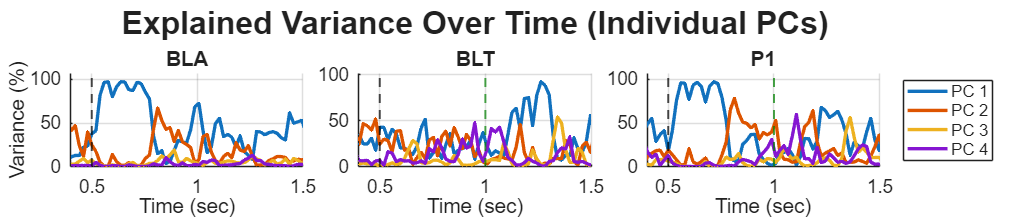


target_pca_conditions = {'BLA', 'BLT', 'P1'}; % Adjust array to plot P2/P3 groups

figure('Position', [50 50 1800 400], 'Name', 'Variance Over Time');
t_var = tiledlayout(1, length(target_pca_conditions), 'TileSpacing', 'compact', 'Padding', 'compact');
title(t_var, 'Explained Variance Over Time (Individual PCs)', 'FontSize', 24, 'FontWeight', 'bold');

for i = 1:length(target_pca_conditions)
    c_name = target_pca_conditions{i};
    nexttile;
    
    var_time = pca_static.(c_name).exp_var_time;
    
    hold on;
    colors = lines(num_comps); 
    
    for k = 1:num_comps
        plot(time_windows, var_time(k, :), 'Color', colors(k,:), ...
            'LineWidth', 2.5, 'DisplayName', sprintf('PC %d', k));
    end
    
    % Overlay stimulus markers
    xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Audio
    if ismember(c_name, {'BLT', 'P1', 'P2_500', 'P2', 'P3_500', 'P3'})
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Tactile
    end
    hold off;
    
    % Limit view to the active region
    xlim([0.4, 1.5]); % Extend to 3.1 if plotting P2_2000
    ylim([0 max(var_time(:))*1.1]); % Dynamically scale Y-axis to max variance
    
    xlabel('Time (sec)');
    if i == 1
        ylabel('Variance (%)'); 
    end
    
    title(strrep(c_name, '_', ' '), 'FontSize', 18);
    grid on; 
    set(gca,'FontSize',14);
    
    if i == length(target_pca_conditions)
        legend('Location', 'eastoutside');
    end
end

%% 2.3 Visualizing Fixed Topoplots & Dynamic Time Courses
disp('Plotting Fixed Topoplots and Dynamic Time Courses...');

Plotting Fixed Topoplots and Dynamic Time Courses...


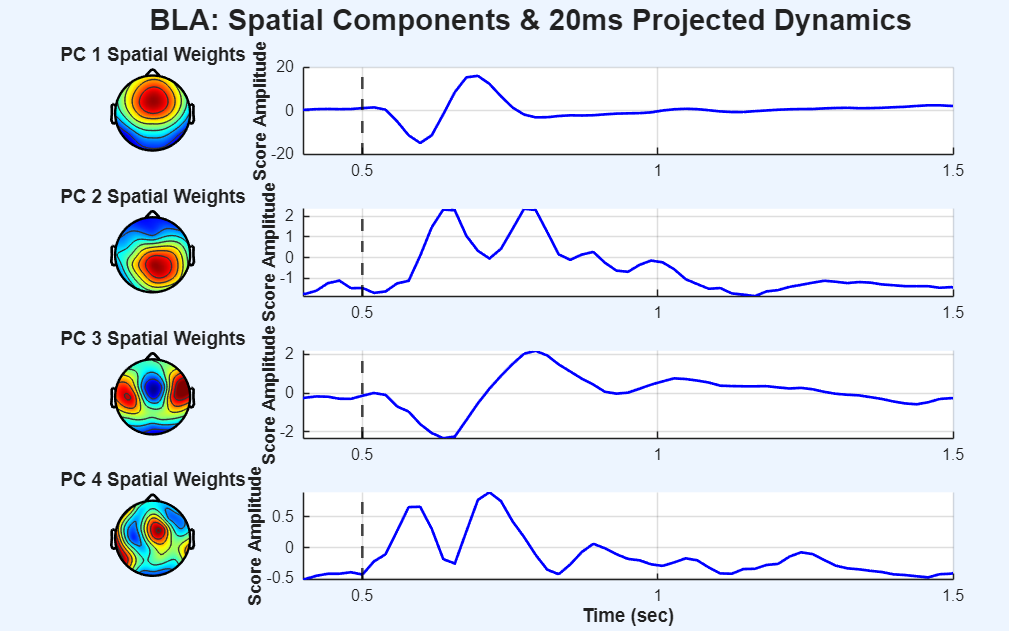

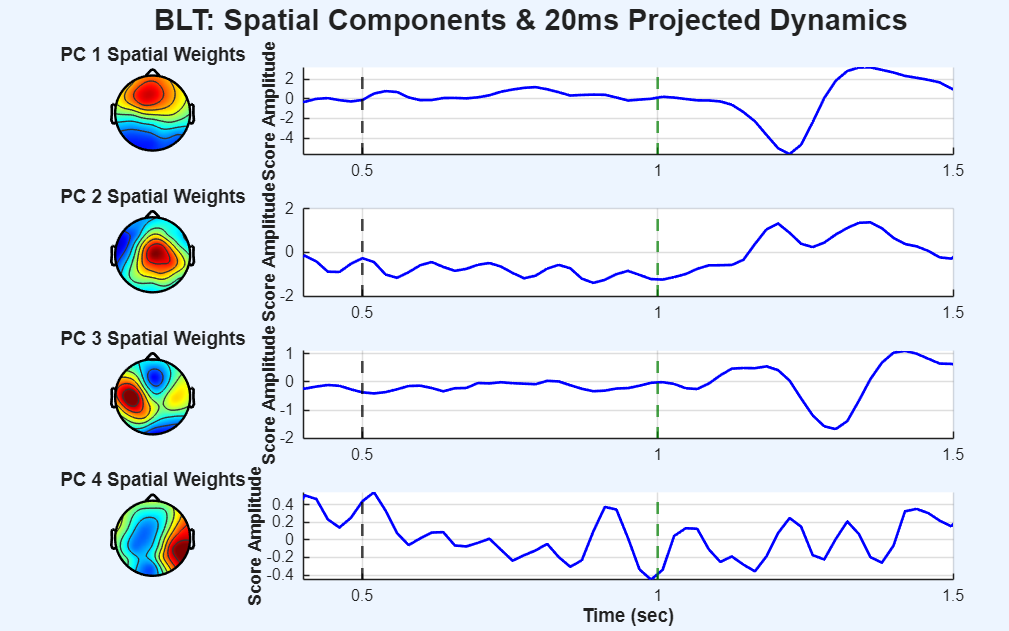

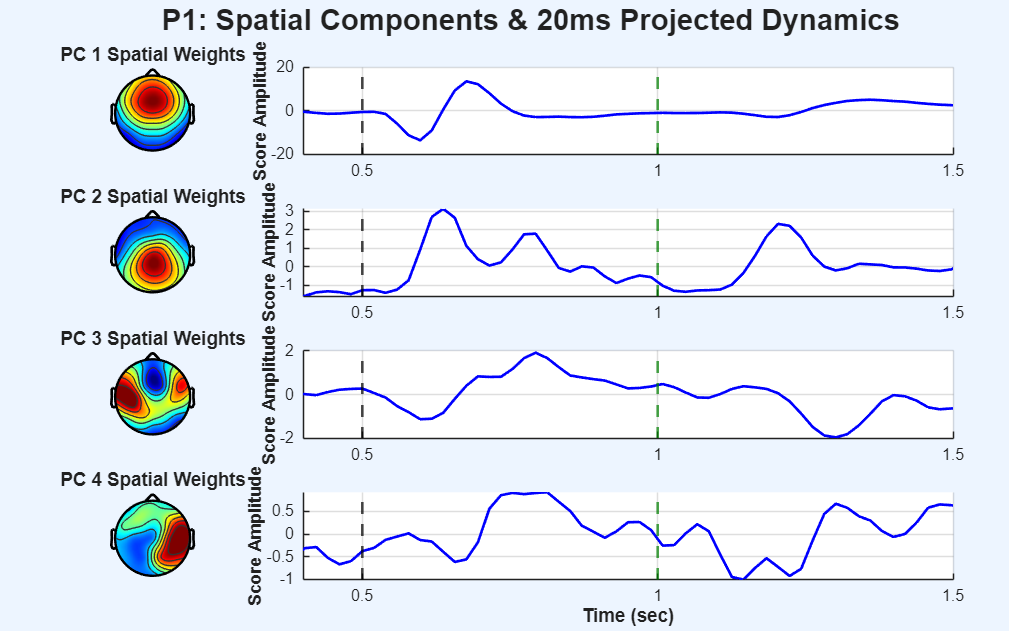

warning('off', 'all');

num_comps_plot = 4;
dark_green  = [0 0.5 0];
target_conds = {'BLA', 'BLT', 'P1'}; 

for cond_i = 1:length(target_conds)
    c_name = target_conds{cond_i};
    clean_name = strrep(c_name, '_', ' ');
    
    fig_name = sprintf('PCA Space & Dynamics: %s', clean_name);
    figure('Position', [100, 100, 1600, 1000], 'Name', fig_name);
    
    % Layout: 4 Rows (PCs). Column 1: Topoplot (1 width), Column 2: Trace (3 width)
    t = tiledlayout(num_comps_plot, 4, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(t, sprintf('%s: Spatial Components & 20ms Projected Dynamics', clean_name), 'FontSize', 22, 'FontWeight', 'bold');
    
    % Extract Data
    coeff_fixed = pca_static.(c_name).coeff;
    comp_time = pca_static.(c_name).comp_time;
    
    max_topo = max(abs(coeff_fixed(:)));
    clim_bound = [-max_topo, max_topo] * 0.8;
    
    for pc = 1:num_comps_plot
        
        % 1. PLOT FIXED TOPOPLOT (Takes up 1 tile slot)
        nexttile([1 1]); 
        topoplot(coeff_fixed(:, pc), EEG.chanlocs, 'electrodes', 'off', 'maplimits', clim_bound);
        title(sprintf('PC %d Spatial Weights', pc), 'FontSize', 14, 'FontWeight', 'bold');
        
        % 2. PLOT DYNAMIC TIME COURSE (Takes up 3 tile slots)
        nexttile([1 3]);
        hold on;
        plot(time_windows, comp_time(pc, :), 'b', 'LineWidth', 2);
        
        % Add markers
        xline(0.5, 'k--', 'LineWidth', 2);
        if ismember(c_name, {'BLT', 'P1'})
            xline(1.0, '--', 'Color', dark_green, 'LineWidth', 2);
        end
        hold off;
        
        % Focus on the region of interest
        xlim([0.4, 1.5]);
        grid on; set(gca, 'FontSize', 12);
        ylabel('Score Amplitude', 'FontWeight', 'bold');
        if pc == num_comps_plot
            xlabel('Time (sec)', 'FontSize', 14, 'FontWeight', 'bold');
        end
    end
end

warning('on', 'all');

%% 3.0 Cross-Condition Cosine Similarity (Macro-Windows)
disp('Calculating Cross-Condition Cosine Similarities...');

Calculating Cross-Condition Cosine Similarities...


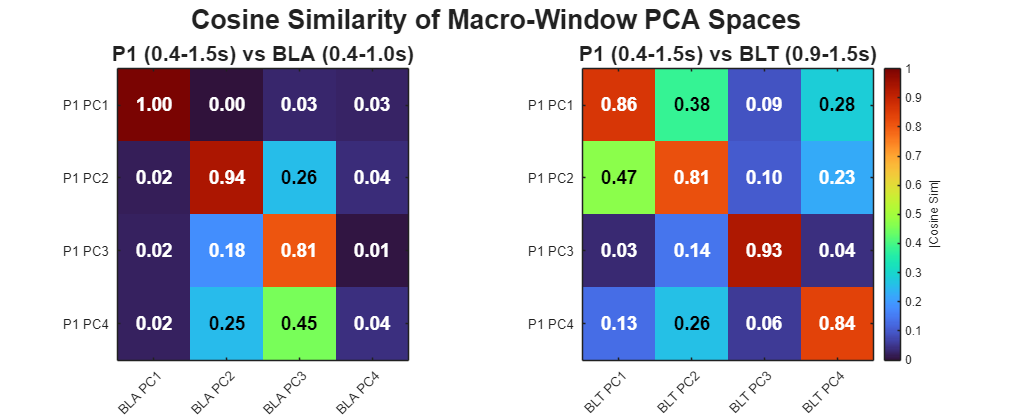


num_comps_sim = 4; 

% We are comparing the FIXED macro-window components directly.
% e.g., P1 (0.4-1.5s) vs BLA (0.4-1.0s)
pairs = {
    {'P1', 'BLA', 'P1 (0.4-1.5s) vs BLA (0.4-1.0s)'},
    {'P1', 'BLT', 'P1 (0.4-1.5s) vs BLT (0.9-1.5s)'}
};

figure('Position', [100, 100, 1200, 500], 'Name', 'Macro-Subspace Similarity');
t = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Cosine Similarity of Macro-Window PCA Spaces', 'FontSize', 20, 'FontWeight', 'bold');

for p = 1:length(pairs)
    condA = pairs{p}{1};
    condB = pairs{p}{2};
    title_str = pairs{p}{3};
    
    % Extract the fixed spatial coefficients 
    c_A = pca_static.(condA).coeff(:, 1:num_comps_sim);
    c_B = pca_static.(condB).coeff(:, 1:num_comps_sim);
    
    % Calculate 4x4 absolute cosine similarity (Dot Product)
    sim_mat = abs(c_A' * c_B);
    
    % Plotting
    nexttile;
    imagesc(sim_mat);
    colormap('turbo'); caxis([0 1]); pbaspect([1 1 1]); 
    
    xticks(1:num_comps_sim); yticks(1:num_comps_sim);
    xticklabels(arrayfun(@(x) sprintf('%s PC%d', condB, x), 1:num_comps_sim, 'UniformOutput', false));
    yticklabels(arrayfun(@(x) sprintf('%s PC%d', condA, x), 1:num_comps_sim, 'UniformOutput', false));
    xtickangle(45);
    title(title_str, 'FontSize', 16, 'FontWeight', 'bold');
    
    % Overlay numerical text
    for r = 1:num_comps_sim
        for c = 1:num_comps_sim
            val = sim_mat(r,c);
            text_color = 'k'; if val < 0.25 || val > 0.8, text_color = 'w'; end
            text(c, r, sprintf('%.2f', val), 'HorizontalAlignment', 'center', 'Color', text_color, 'FontSize', 14, 'FontWeight', 'bold');
        end
    end
    
    if p == 2
        cb = colorbar; cb.Label.String = '|Cosine Sim|'; 
    end
end

## 2.0 Macro-Window PCA with 20ms Sliding Projections

%% 2.0 Targeted Sliding Window PCA (63ms Window, 20ms Step)
disp('Performing Targeted Sliding Window PCA...');

Performing Targeted Sliding Window PCA...



pca_conditions = {'BLA', 'BLT', 'P1','P2_500', 'P2_2000', 'P2', 'P3_500', 'P3_missing', 'P3'};
num_comps = 4; 

% Turn off the annoying PCA rank deficiency warning
warning('off', 'stats:pca:ColRankDefX'); 

% Define Sliding Window Parameters
win_ms = 64; 
step_ms = 20; 

if isempty(fs), fs = EEG.srate; end 
win_samples = round((win_ms / 1000) * fs);
step_samples = round((step_ms / 1000) * fs);

% Create a GLOBAL time vector so all conditions stay perfectly aligned
total_samples = length(time_ms_eeg);
win_starts_global = 1:step_samples:(total_samples - win_samples + 1);
n_windows_global = length(win_starts_global);

time_windows_global = zeros(1, n_windows_global);
for w = 1:n_windows_global
    idx = win_starts_global(w):(win_starts_global(w) + win_samples - 1);
    time_windows_global(w) = mean(time_ms_eeg(idx)); 
end

pca_dynamic = struct();

for i = 1:length(pca_conditions)
    c_name = pca_conditions{i};
    X = data_grand_avg.(c_name); 
    
    % Define specific testing windows per condition
    % (Inside your Section 2.0 loop)
    if strcmp(c_name, 'BLA')
        t_bounds = [0.4, 1.0];
    elseif strcmp(c_name, 'BLT')
        t_bounds = [0.9, 1.5];
    elseif ismember(c_name, {'P2_2000', 'P2'})
        t_bounds = [0.4, 3.1]; % Extended window for delayed condition
    else 
        t_bounds = [0.4, 1.5]; % P1, P2_500, P3 variants, etc.
    end
    
    % Find which global windows fall into this condition's testing boundaries
    valid_win_mask = time_windows_global >= t_bounds(1) & time_windows_global <= t_bounds(2);
    valid_win_idx = find(valid_win_mask);
    n_valid = length(valid_win_idx);
    
    % Pre-allocate strictly for the valid windows
    coeffs_time = zeros(num_ch, num_comps, n_valid);
    exp_var_time = zeros(num_comps, n_valid);
    comp_time_matrix = zeros(num_comps, n_valid);
    valid_time_vector = time_windows_global(valid_win_idx);
    
    prev_coeff = []; 
    
    for w_local = 1:n_valid
        w_global = valid_win_idx(w_local);
        
        idx = win_starts_global(w_global):(win_starts_global(w_global) + win_samples - 1);
        X_win = X(:, idx);
        
        [coeff, score, ~, ~, exp_var, ~] = pca(X_win');
        
        coeff = coeff(:, 1:min(num_comps, size(coeff,2)));
        score = score(:, 1:min(num_comps, size(score,2))); 
        exp_var = exp_var(1:min(num_comps, length(exp_var)));
        
        % Simple Sign Alignment (Prevents visual flashing, does NOT reorder components)
        if w_local > 1
            for pc = 1:size(coeff, 2)
                if dot(prev_coeff(:, pc), coeff(:, pc)) < 0
                    coeff(:, pc) = -coeff(:, pc);
                    score(:, pc) = -score(:, pc);
                end
            end
        end
        
        prev_coeff = coeff;
        coeffs_time(:, 1:size(coeff,2), w_local) = coeff;
        exp_var_time(1:length(exp_var), w_local) = exp_var;
        comp_time_matrix(1:size(score,2), w_local) = mean(score, 1)';
    end
    
    pca_dynamic.(c_name).coeffs = coeffs_time;        
    pca_dynamic.(c_name).exp_var = exp_var_time;      
    pca_dynamic.(c_name).comp_time = comp_time_matrix; 
    pca_dynamic.(c_name).time_vector = valid_time_vector; 
end
warning('on', 'stats:pca:ColRankDefX'); 

## 2.0.b Extract Single-Subject Scores & Variance using the Master PCA Space


disp('Projecting single-subject data into the Grand-Average PCA space...');

Projecting single-subject data into the Grand-Average PCA space...



stats_across_subjects = struct();

for i = 1:length(pca_conditions)
    c_name = pca_conditions{i};
    num_subjects = length(data_all_conds.(c_name));
    
    % --- THE FIX: Unified t_bounds for ALL conditions ---
    if strcmp(c_name, 'BLA')
        t_bounds = [0.4, 1.0];
    elseif strcmp(c_name, 'BLT')
        t_bounds = [0.9, 1.5];
    elseif ismember(c_name, {'P2_2000', 'P2'})
        t_bounds = [0.4, 3.1]; % Extended window for delayed conditions
    else 
        t_bounds = [0.4, 1.5]; % P1, P2_500, P3 variants, etc.
    end
    % ----------------------------------------------------
    
    valid_win_mask = time_windows_global >= t_bounds(1) & time_windows_global <= t_bounds(2);
    valid_win_idx = find(valid_win_mask);
    n_valid = length(valid_win_idx);
    
    % Pre-allocate arrays for Scores AND Variance
    all_subj_scores = zeros(num_comps, n_valid, num_subjects);
    all_subj_var = zeros(num_comps, n_valid, num_subjects); 
    
    for s = 1:num_subjects
        subj_erp = mean(data_all_conds.(c_name){s}, 3, 'omitnan');
        
        for w_local = 1:n_valid
            w_global = valid_win_idx(w_local);
            idx = win_starts_global(w_global):(win_starts_global(w_global) + win_samples - 1);
            
            subj_win = subj_erp(:, idx);
            master_coeff = pca_dynamic.(c_name).coeffs(:, :, w_local);
            
            % 1. Calculate Score (Amplitude)
            subj_mu = mean(subj_win', 1);
            subj_score = (subj_win' - subj_mu) * master_coeff;
            all_subj_scores(:, w_local, s) = mean(subj_score, 1)';
            
            % 2. Calculate Explained Variance %
            total_win_var = sum(var(subj_win', 0, 1));
            if total_win_var == 0, total_win_var = 1; end % Safety catch
            all_subj_var(:, w_local, s) = (var(subj_score, 0, 1)' / total_win_var) * 100;
        end
    end
    
    % Store the Means and Standard Deviations across all subjects
    stats_across_subjects.(c_name).score_mean = mean(all_subj_scores, 3, 'omitnan'); 
    stats_across_subjects.(c_name).score_std  = std(all_subj_scores, 0, 3, 'omitnan'); 
    
    stats_across_subjects.(c_name).var_mean = mean(all_subj_var, 3, 'omitnan'); 
    stats_across_subjects.(c_name).var_std  = std(all_subj_var, 0, 3, 'omitnan'); 
end
disp('Subject-level projections and statistics complete.');

Subject-level projections and statistics complete.


## 2.1 Plot Explained Variance Across Sliding Windows

disp('Plotting Cumulative Explained Variance...');

Plotting Cumulative Explained Variance...


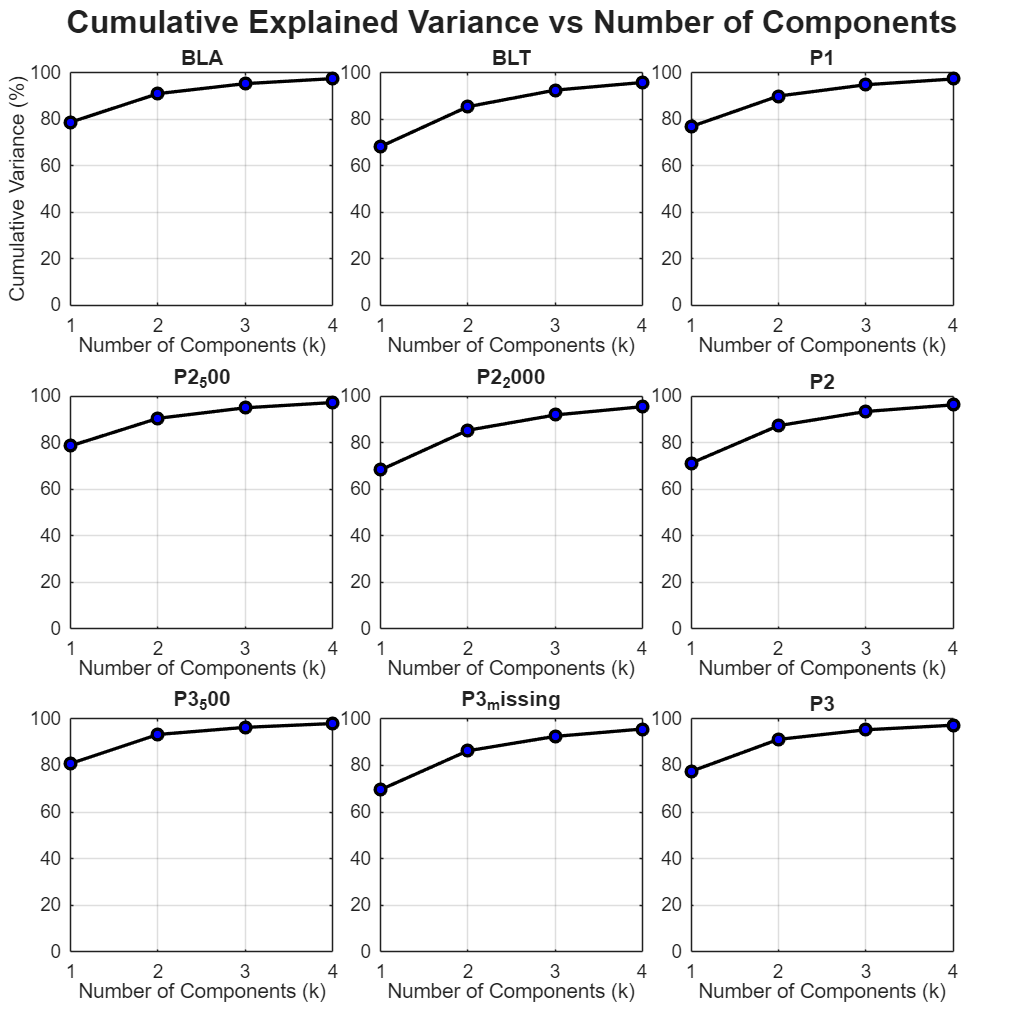


figure('Position', [50 50 1200 1200], 'Name', 'Cumulative Variance');
t = tiledlayout(3, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Cumulative Explained Variance vs Number of Components', 'FontSize', 24, 'FontWeight', 'bold');

for i = 1:length(pca_conditions)
    c_name = pca_conditions{i};
    nexttile;
    
    % Average the explained variance across all sliding windows (Dim 2)
    mean_exp_var = mean(pca_dynamic.(c_name).exp_var, 2);
    
    % Calculate cumulative sum to get the total variance explained up to k
    cum_var = cumsum(mean_exp_var);
    
    % Plot the Pareto/Scree curve
    plot(1:num_comps, cum_var, '-ok', 'LineWidth', 2.5, 'MarkerFaceColor', 'b', 'MarkerSize', 8);
    
    xlim([1 num_comps]);
    ylim([0 100]); % Assuming explained variance is a percentage 0-100
    xticks(1:num_comps);
    
    xlabel('Number of Components (k)');
    if i == 1
        ylabel('Cumulative Variance (%)'); 
    end
    title(c_name, 'FontSize', 18);
    grid on; 
    set(gca,'FontSize',14);
end

## 2.2 Plotting Individual Explained Variance Over Time

disp('Plotting Individual Explained Variance Over Time...');

Plotting Individual Explained Variance Over Time...


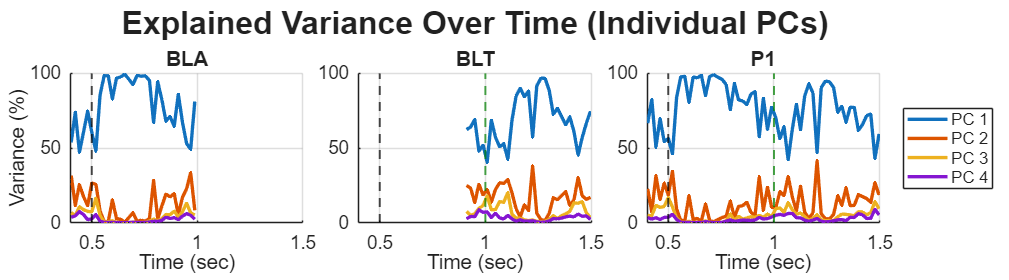


target_pca_conditions = {'BLA', 'BLT', 'P1'}; 

figure('Position', [50 50 1800 500], 'Name', 'Individual Variance Over Time');
t_var = tiledlayout(1, length(target_pca_conditions), 'TileSpacing', 'compact', 'Padding', 'compact');
title(t_var, 'Explained Variance Over Time (Individual PCs)', 'FontSize', 24, 'FontWeight', 'bold');

for i = 1:length(target_pca_conditions)
    c_name = target_pca_conditions{i};
    nexttile;
    
    var_time = pca_dynamic.(c_name).exp_var; % Raw variance (not cumsum)
    
    hold on;
    colors = lines(num_comps); 
    for k = 1:num_comps
        plot(pca_dynamic.(c_name).time_vector, var_time(k, :), 'Color', colors(k,:), ...
            'LineWidth', 2.5, 'DisplayName', sprintf('PC %d', k));
    end
    
    % Overlay stimulus markers
    xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off'); 
    if ismember(c_name, {'BLT', 'P1'})
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 1.5, 'HandleVisibility', 'off'); 
    end
    hold off;
    
    xlim([0.4, 1.5]);
    ylim([0 100]); 
    
    xlabel('Time (sec)');
    if i == 1, ylabel('Variance (%)'); end
    
    title(strrep(c_name, '_', ' '), 'FontSize', 18);
    grid on; set(gca,'FontSize',14);
    
    if i == length(target_pca_conditions)
        legend('Location', 'eastoutside');
    end
end

## 2.1.b Plotting Group-Level Explained Variance (with Std Dev Ribbons)

disp('Plotting Group-Level Explained Variance Over Time...');

Plotting Group-Level Explained Variance Over Time...


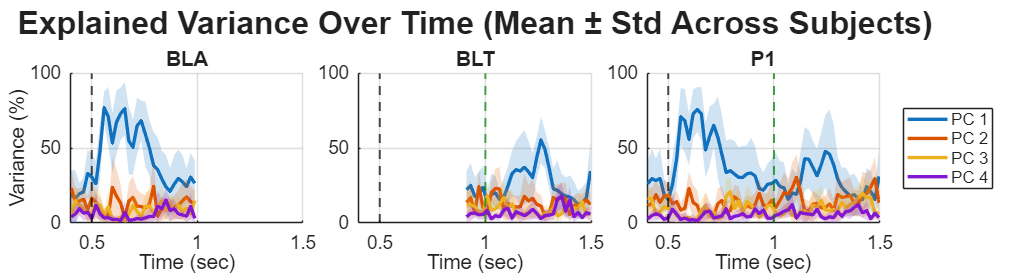


target_pca_conditions = {'BLA', 'BLT', 'P1'}; 

figure('Position', [50 50 1800 500], 'Name', 'Group Variance Over Time');
t_var = tiledlayout(1, length(target_pca_conditions), 'TileSpacing', 'compact', 'Padding', 'compact');
title(t_var, 'Explained Variance Over Time (Mean ± Std Across Subjects)', 'FontSize', 24, 'FontWeight', 'bold');

for i = 1:length(target_pca_conditions)
    c_name = target_pca_conditions{i};
    nexttile;
    
    % Extract the newly computed Mean and Std Dev matrices
    var_mu = stats_across_subjects.(c_name).var_mean; 
    var_sd = stats_across_subjects.(c_name).var_std;
    time_vec = pca_dynamic.(c_name).time_vector;
    
    hold on;
    colors = lines(num_comps); 
    
    for k = 1:num_comps
        mu_k = var_mu(k, :);
        sd_k = var_sd(k, :);
        
        % 1. Create the Shaded Error Ribbon (patch)
        % We concatenate the time vector going forward, then backward to draw a polygon
        x_patch = [time_vec, fliplr(time_vec)];
        y_patch = [mu_k + sd_k, fliplr(mu_k - sd_k)];
        
        % Draw the ribbon with 20% opacity ('FaceAlpha', 0.2)
        patch(x_patch, y_patch, colors(k,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        
        % 2. Draw the solid Mean line on top
        plot(time_vec, mu_k, 'Color', colors(k,:), 'LineWidth', 2.5, 'DisplayName', sprintf('PC %d', k));
    end
    
    % Overlay stimulus markers
    xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off'); 
    if ismember(c_name, {'BLT', 'P1'})
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 1.5, 'HandleVisibility', 'off'); 
    end
    hold off;
    
    % Format Axes
    xlim([0.4, 1.5]);
    ylim([0 100]); 
    
    xlabel('Time (sec)');
    if i == 1, ylabel('Variance (%)'); end
    
    title(strrep(c_name, '_', ' '), 'FontSize', 18);
    grid on; set(gca,'FontSize',14);
    
    if i == length(target_pca_conditions)
        legend('Location', 'eastoutside');
    end
end

## 2.2 Visualizing Dynamic Topoplots & Time Courses (100ms Windows)

disp('Plotting Dynamic Topoplots and Time Courses (100ms chunks)...');

Plotting Dynamic Topoplots and Time Courses (100ms chunks)...


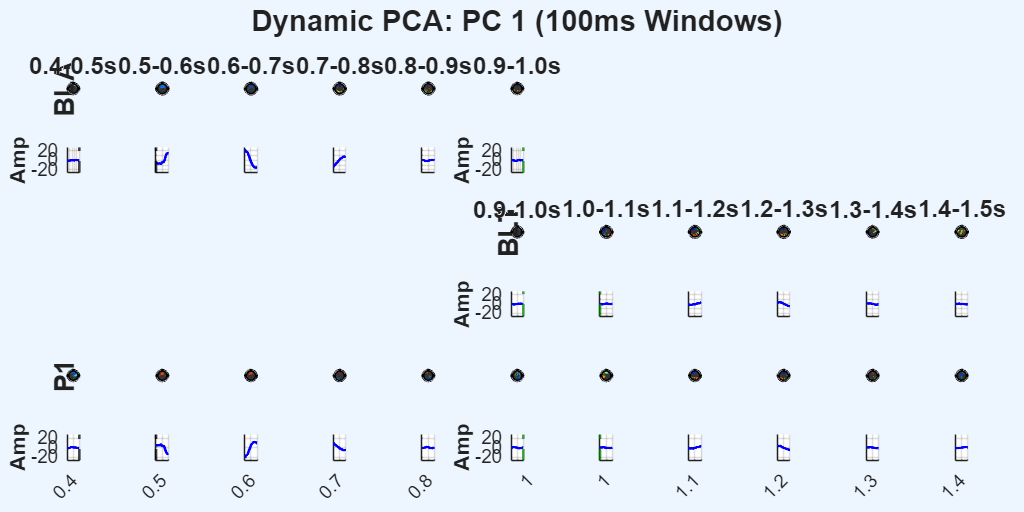

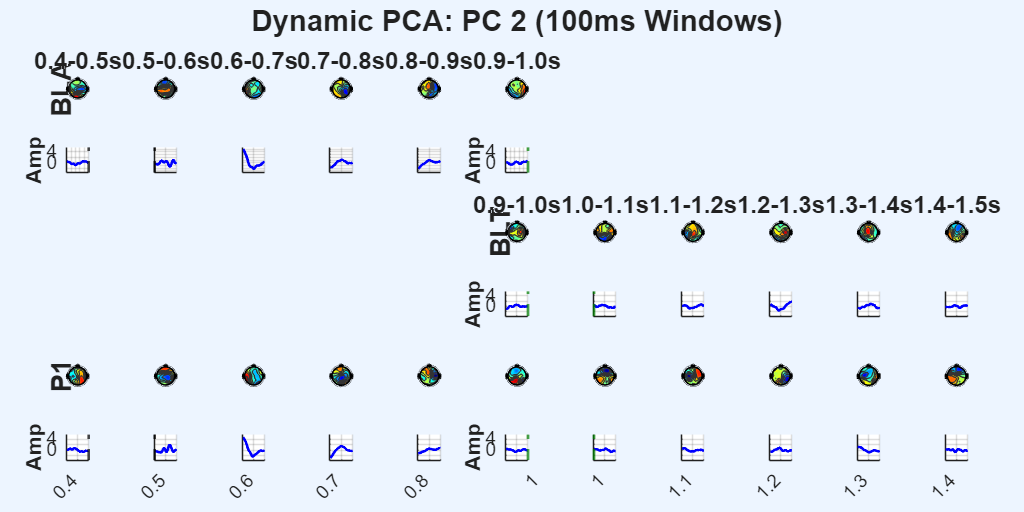

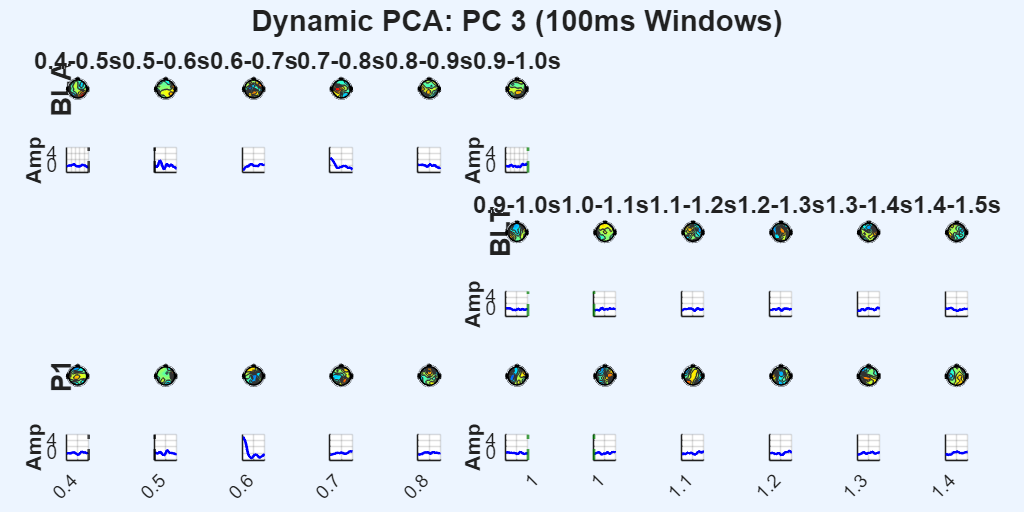

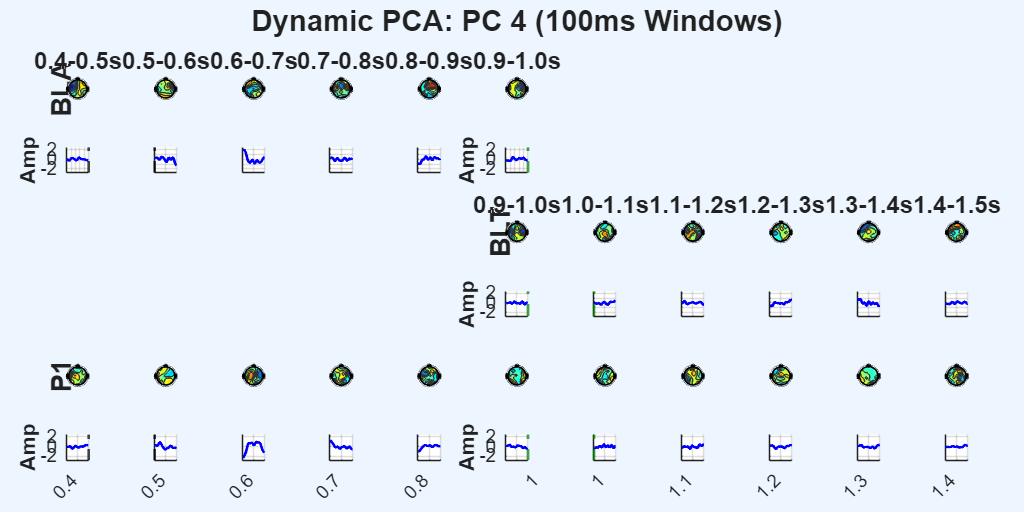

warning('off', 'all');

num_comps_plot = 4;
target_conds = {'BLA', 'BLT', 'P1'};
num_conds = length(target_conds);

% 1. Define Fixed 100ms Plotting Windows from 0.4s to 1.5s
plot_starts = 0.400 : 0.100 : 1.400; % [0.4, 0.5, 0.6 ... 1.4]
plot_ends   = 0.500 : 0.100 : 1.500; % [0.5, 0.6, 0.7 ... 1.5]
num_plot_windows = length(plot_starts);

for pc = 1:num_comps_plot
    fig_name = sprintf('Dynamic PCA: PC %d (100ms Windows)', pc);
    % Make figure very wide to accommodate 11 columns of 100ms chunks
    figure('Position', [50, 50, 2400, 1200], 'Name', fig_name);
    
    t = tiledlayout(num_conds * 2, num_plot_windows, 'TileSpacing', 'tight', 'Padding', 'compact');
    title(t, fig_name, 'FontSize', 22, 'FontWeight', 'bold');
    
    % --- CRITICAL: Calculate Global Y-Limits for this PC across ALL conditions ---
    min_val = inf; max_val = -inf;
    for cond_idx = 1:num_conds
        c_name = target_conds{cond_idx};
        
        % Explicitly define the boundaries for this condition
        if strcmp(c_name, 'BLA')
            valid_range = [0.4, 1.0];
        elseif strcmp(c_name, 'BLT')
            valid_range = [0.9, 1.5];
        else
            valid_range = [0.4, 1.5];
        end
        
        for col = 1:num_plot_windows
             t_start = plot_starts(col);
             t_end = plot_ends(col);
             t_center = (t_start + t_end) / 2;
             
             % Skip calculation if outside this condition's timeframe
             if t_start < valid_range(1) - 0.001 || t_end > valid_range(2) + 0.001
                 continue;
             end
             
             [~, w_local] = min(abs(pca_dynamic.(c_name).time_vector - t_center));
             
             idx = find(time_ms_eeg >= t_start & time_ms_eeg < t_end);
             if ~isempty(idx)
                 X_win = data_grand_avg.(c_name)(:, idx);
                 mu = mean(X_win', 1);
                 trace = (X_win' - mu) * pca_dynamic.(c_name).coeffs(:, pc, w_local);
                 min_val = min(min_val, min(trace));
                 max_val = max(max_val, max(trace));
             end
        end
    end
    pad = (max_val - min_val) * 0.1;
    if pad == 0, pad = 1; end
    trace_limits = [min_val - pad, max_val + pad];
    
    % Generate the Plot Grid
    for cond_idx = 1:num_conds
        c_name = target_conds{cond_idx};
        clean_name = strrep(c_name, '_', ' ');
        
        % Explicitly define the boundaries for this condition again for the plotting loop
        if strcmp(c_name, 'BLA')
            valid_range = [0.4, 1.0];
        elseif strcmp(c_name, 'BLT')
            valid_range = [0.9, 1.5];
        else
            valid_range = [0.4, 1.5];
        end
        
        % Global Color Scale for Topoplots for this condition
        max_topo = max(abs(pca_dynamic.(c_name).coeffs(:, pc, :)), [], 'all');
        clim_bound = [-max_topo, max_topo] * 0.8;
        if clim_bound(2) == 0, clim_bound = [-1 1]; end 
        
        for col = 1:num_plot_windows
            t_start = plot_starts(col);
            t_end   = plot_ends(col);
            t_center = (t_start + t_end) / 2;
            
            topo_tile_idx = (cond_idx - 1) * 2 * num_plot_windows + col;
            trace_tile_idx = ((cond_idx - 1) * 2 + 1) * num_plot_windows + col;
            
            % HARD BOUNDARY CHECK: If the condition doesn't span this time, leave it blank!
            if t_start < valid_range(1) - 0.001 || t_end > valid_range(2) + 0.001
                nexttile(topo_tile_idx); axis off;
                nexttile(trace_tile_idx); axis off;
                continue;
            end
            
            % Find the nearest spatial weights for this 100ms chunk
            [~, w_local] = min(abs(pca_dynamic.(c_name).time_vector - t_center));
            
            % 1. Plot Topoplot
            nexttile(topo_tile_idx);
            spatial_weights = pca_dynamic.(c_name).coeffs(:, pc, w_local);
            topoplot(spatial_weights, EEG.chanlocs, 'electrodes', 'off', 'maplimits', clim_bound);
            
            % Add Headers (Top Row Only)
            if cond_idx == 1 || (cond_idx == 2 && strcmp(c_name, 'BLT') && t_center > 0.85)
                title(sprintf('%.1f-%.1fs', t_start, t_end), 'FontSize', 18, 'FontWeight', 'bold');
            end
            
            % Condition Row Label (Leftmost Column)
            if (col == 1 && ~strcmp(c_name, 'BLT')) || (col == 6 && strcmp(c_name, 'BLT'))
                text(-0.8, 0, clean_name, 'FontSize', 20, 'FontWeight', 'bold', 'Rotation', 90, 'HorizontalAlignment', 'center');
            end
            
            % 2. Plot Trace
            nexttile(trace_tile_idx);
            hold on;
            idx = find(time_ms_eeg >= t_start & time_ms_eeg < t_end);
            time_win = time_ms_eeg(idx);
            X_win = data_grand_avg.(c_name)(:, idx);
            mu = mean(X_win', 1);
            trace = (X_win' - mu) * pca_dynamic.(c_name).coeffs(:, pc, w_local);
            
            plot(time_win, trace, 'b', 'LineWidth', 2);
            
            % Event Lines (Draw if the event falls inside this specific 100ms window)
            if 0.5 >= t_start && 0.5 <= t_end
                xline(0.5, 'k--', 'LineWidth', 2);
            end
            if 1.0 >= t_start && 1.0 <= t_end
                xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
            end
            hold off;
            
            xlim([t_start, t_end]);
            ylim(trace_limits); % Unified limits applied here!
            grid on;
            
            % Format Axes to prevent clutter
            if cond_idx < num_conds
                xticklabels({});
            else
                set(gca, 'FontSize', 14);
                xtickangle(45);
            end
            
            if col > 1 && col ~= 6
                yticklabels({});
            else
                set(gca, 'FontSize', 14);
                ylabel('Amp', 'FontSize', 16, 'FontWeight', 'bold');
            end
        end
    end
end

warning('on', 'all');
warning('on', 'all');
warning('on', 'all');

%% 3.0 Matched Cosine Similarity
disp('Calculating Matched Cross-Condition Cosine Similarities...');

Calculating Matched Cross-Condition Cosine Similarities...


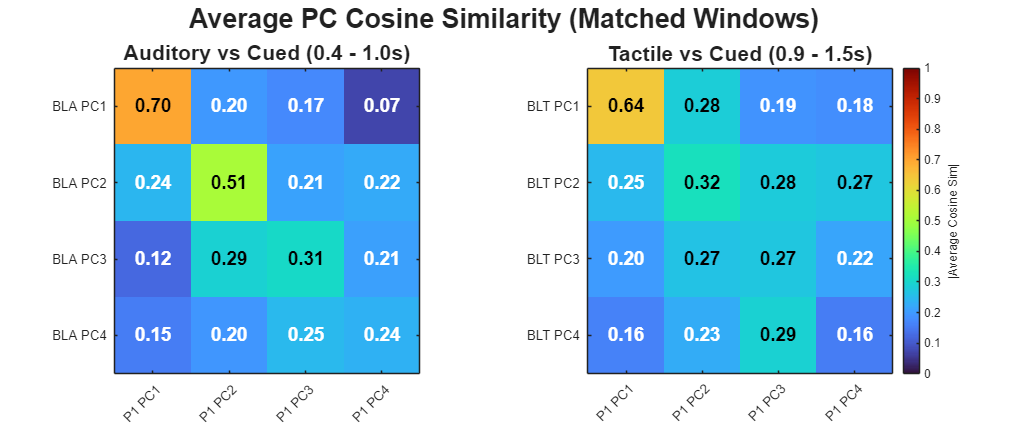


num_comps_sim = 4; 

% We are comparing specific overlapping periods
pairs = {
    {'BLA', 'P1', 'Auditory vs Cued (0.4 - 1.0s)', 0.4, 1.0},
    {'BLT', 'P1', 'Tactile vs Cued (0.9 - 1.5s)', 0.9, 1.5}
};

figure('Position', [100, 100, 1200, 500], 'Name', 'Matched Cosine Similarity');
t = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Average PC Cosine Similarity (Matched Windows)', 'FontSize', 20, 'FontWeight', 'bold');

for p = 1:length(pairs)
    condA = pairs{p}{1};
    condB = pairs{p}{2};
    title_str = pairs{p}{3};
    t_start = pairs{p}{4};
    t_end = pairs{p}{5};
    
    time_A = pca_dynamic.(condA).time_vector;
    time_B = pca_dynamic.(condB).time_vector;
    
    % Find the shared time points that fall inside the requested bounds
    valid_A = find(time_A >= t_start - 0.001 & time_A <= t_end + 0.001);
    valid_B = find(time_B >= t_start - 0.001 & time_B <= t_end + 0.001);
    
    % Mathematically align them to ensure we only compare matching 20ms steps
    [shared_times, idx_A, idx_B] = intersect(time_A(valid_A), time_B(valid_B));
    
    % Map back to the local indices for matrix extraction
    final_idx_A = valid_A(idx_A);
    final_idx_B = valid_B(idx_B);
    num_shared_wins = length(shared_times);
    
    sim_mat_time = zeros(num_comps_sim, num_comps_sim, num_shared_wins);
    
    for w_idx = 1:num_shared_wins
        c_A = pca_dynamic.(condA).coeffs(:, 1:num_comps_sim, final_idx_A(w_idx));
        c_B = pca_dynamic.(condB).coeffs(:, 1:num_comps_sim, final_idx_B(w_idx));
        
        sim_mat_time(:, :, w_idx) = abs(c_A' * c_B);
    end
    
    mean_sim_mat = mean(sim_mat_time, 3);
    
    % Plotting
    nexttile;
    imagesc(mean_sim_mat);
    colormap('turbo'); caxis([0 1]); pbaspect([1 1 1]); 
    
    xticks(1:num_comps_sim); yticks(1:num_comps_sim);
    xticklabels(arrayfun(@(x) sprintf('%s PC%d', condB, x), 1:num_comps_sim, 'UniformOutput', false));
    yticklabels(arrayfun(@(x) sprintf('%s PC%d', condA, x), 1:num_comps_sim, 'UniformOutput', false));
    xtickangle(45);
    title(title_str, 'FontSize', 16, 'FontWeight', 'bold');
    
    for r = 1:num_comps_sim
        for c = 1:num_comps_sim
            val = mean_sim_mat(r,c);
            text_color = 'k'; if val < 0.25 || val > 0.8, text_color = 'w'; end
            text(c, r, sprintf('%.2f', val), 'HorizontalAlignment', 'center', 'Color', text_color, 'FontSize', 14, 'FontWeight', 'bold');
        end
    end
    
    if p == 2
        cb = colorbar; cb.Label.String = '|Average Cosine Sim|'; 
    end
end

## 3.0 Plotting Cumulative Explained Variance (P1 vs P2 Variations)

%% 3.1 Plotting Individual Explained Variance (P1 vs P2 Variations)
disp('Plotting Individual Explained Variance (P2 Variations)...');

Plotting Individual Explained Variance (P2 Variations)...


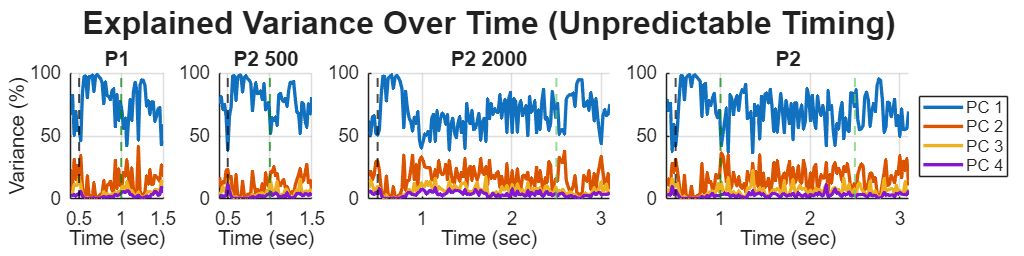


target_pca_conditions = {'P1', 'P2_500', 'P2_2000', 'P2'};

% Widen the figure to accommodate the proportional axes
figure('Position', [50 50 2000 500], 'Name', 'Individual Variance Over Time');

% Create a 6-column grid so we can span multiple columns for the longer conditions
t_var = tiledlayout(1, 6, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t_var, 'Explained Variance Over Time (Unpredictable Timing)', 'FontSize', 24, 'FontWeight', 'bold');

for i = 1:length(target_pca_conditions)
    c_name = target_pca_conditions{i};
    
    % Dynamically set tile span and X-limits based on condition length
    if ismember(c_name, {'P1', 'P2_500'})
        nexttile([1 1]); % Takes 1 column width
        x_limit = [0.4, 1.5];
    else
        nexttile([1 2]); % Takes 2 columns width (doubling the X-axis!)
        x_limit = [0.4, 3.1];
    end
    
    var_time = pca_dynamic.(c_name).exp_var;
    time_vec = pca_dynamic.(c_name).time_vector;
    
    hold on;
    colors = lines(num_comps); 
    
    for k = 1:num_comps
        plot(time_vec, var_time(k, :), 'Color', colors(k,:), 'LineWidth', 2.5, 'DisplayName', sprintf('PC %d', k));
    end
    
    % Overlay stimulus markers
    xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Auditory Cue
    if ismember(c_name, {'P1', 'P2_500', 'P2'})
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Early Tactile
    end
    if ismember(c_name, {'P2_2000', 'P2'})
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Late Tactile
    end
    hold off;
    
    xlim(x_limit);
    ylim([0 100]); 
    
    xlabel('Time (sec)');
    if i == 1, ylabel('Variance (%)'); end
    title(strrep(c_name, '_', ' '), 'FontSize', 18);
    grid on; set(gca,'FontSize',14);
    
    if i == length(target_pca_conditions)
        legend('Location', 'eastoutside'); 
    end
end

## 3.1.b Plotting Group-Level Explained Variance (P2 Variations with Std Dev)

disp('Plotting Group-Level Explained Variance (P2 Variations)...');

Plotting Group-Level Explained Variance (P2 Variations)...


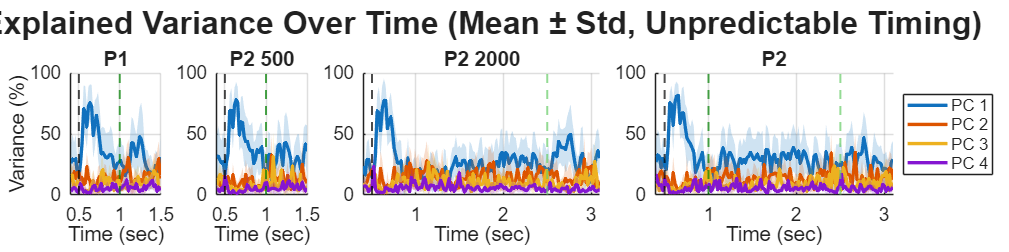


target_pca_conditions = {'P1', 'P2_500', 'P2_2000', 'P2'};

% Widen the figure to accommodate the proportional axes
figure('Position', [50 50 2000 500], 'Name', 'Group Variance Over Time');

% Create a 6-column grid so we can span multiple columns for the longer conditions
t_var = tiledlayout(1, 6, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t_var, 'Explained Variance Over Time (Mean ± Std, Unpredictable Timing)', 'FontSize', 24, 'FontWeight', 'bold');

for i = 1:length(target_pca_conditions)
    c_name = target_pca_conditions{i};
    
    % Dynamically set tile span and X-limits based on condition length
    if ismember(c_name, {'P1', 'P2_500'})
        nexttile([1 1]); % Takes 1 column width
        x_limit = [0.4, 1.5];
    else
        nexttile([1 2]); % Takes 2 columns width (doubling the X-axis!)
        x_limit = [0.4, 3.1];
    end
    
    % Extract the newly computed Mean and Std Dev matrices
    var_mu = stats_across_subjects.(c_name).var_mean;
    var_sd = stats_across_subjects.(c_name).var_std;
    time_vec = pca_dynamic.(c_name).time_vector;
    
    hold on;
    colors = lines(num_comps); 
    
    for k = 1:num_comps
        mu_k = var_mu(k, :);
        sd_k = var_sd(k, :);
        
        % 1. Create the Shaded Error Ribbon (patch)
        % THE FIX: using (:)' guarantees a flat row vector, and flip() works perfectly on it!
        x_patch = [time_vec(:)', flip(time_vec(:)')];
        y_patch = [mu_k(:)' + sd_k(:)', flip(mu_k(:)' - sd_k(:)')];
        
        patch(x_patch, y_patch, colors(k,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        
        % 2. Draw the solid Mean line on top
        plot(time_vec, mu_k, 'Color', colors(k,:), 'LineWidth', 2.5, 'DisplayName', sprintf('PC %d', k));
    end
    
    % Overlay stimulus markers
    xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Auditory Cue
    if ismember(c_name, {'P1', 'P2_500', 'P2'})
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Early Tactile
    end
    if ismember(c_name, {'P2_2000', 'P2'})
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Late Tactile
    end
    hold off;
    
    xlim(x_limit);
    ylim([0 100]); 
    
    xlabel('Time (sec)');
    if i == 1, ylabel('Variance (%)'); end
    title(strrep(c_name, '_', ' '), 'FontSize', 18);
    grid on; set(gca,'FontSize',14);
    
    if i == length(target_pca_conditions)
        legend('Location', 'eastoutside'); 
    end
end

## 3.2 Visualizing Dynamic Topoplots & Time Courses (100ms Windows)


disp('Plotting Dynamic Topoplots and Time Courses (100ms chunks)...');

Plotting Dynamic Topoplots and Time Courses (100ms chunks)...


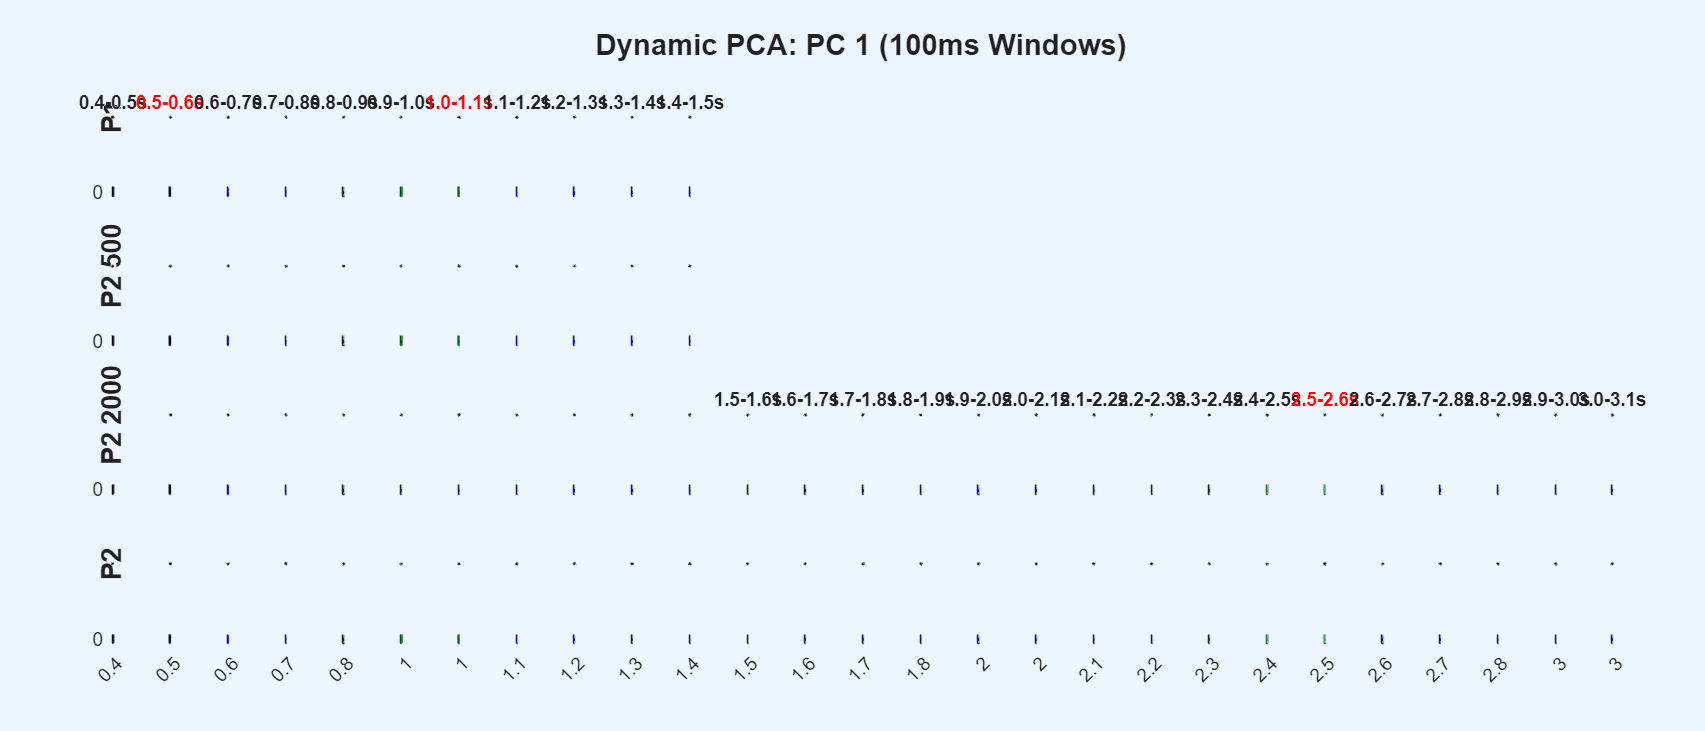

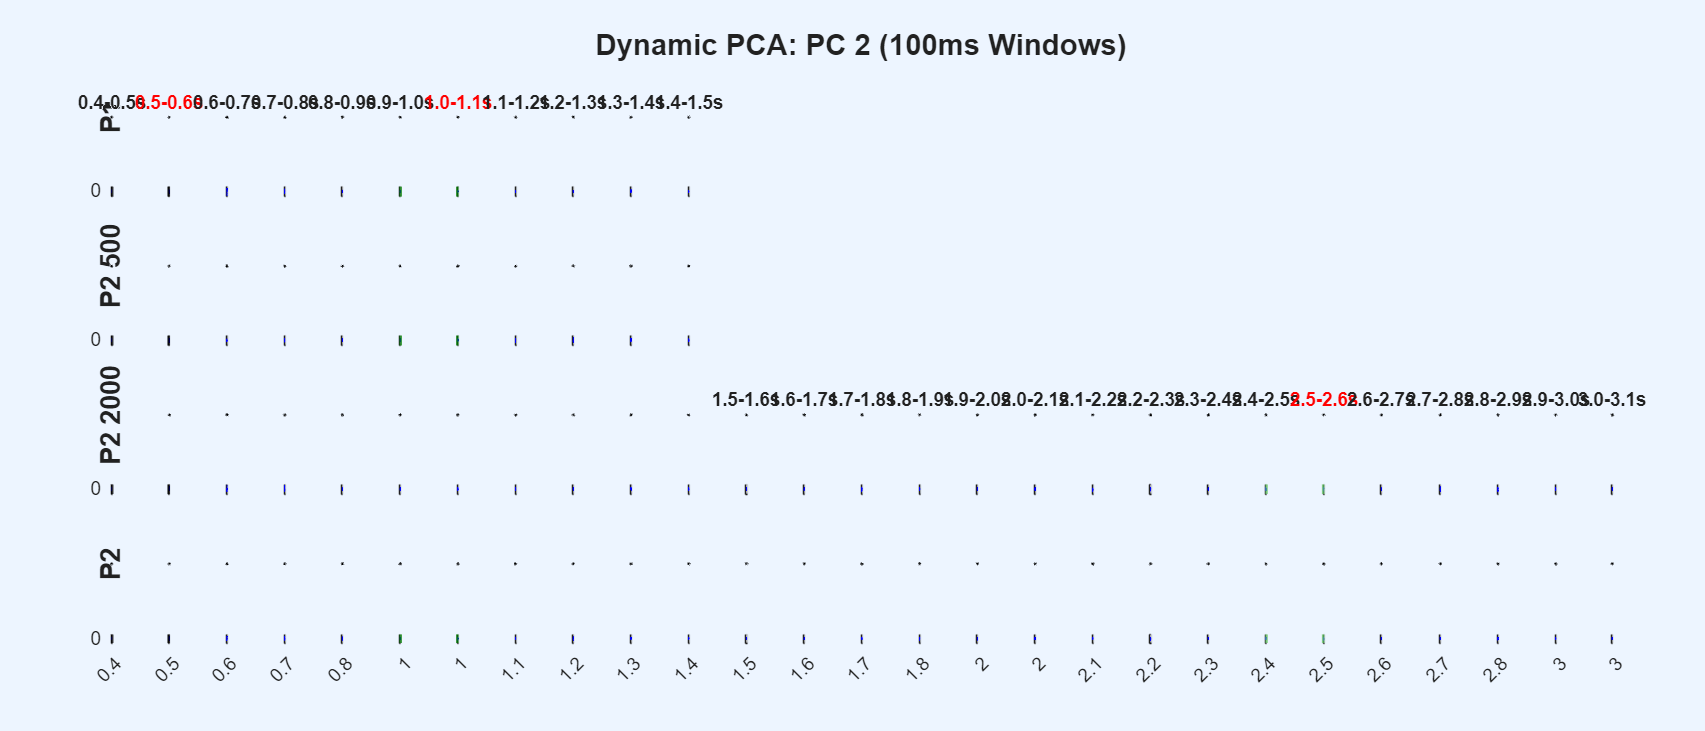

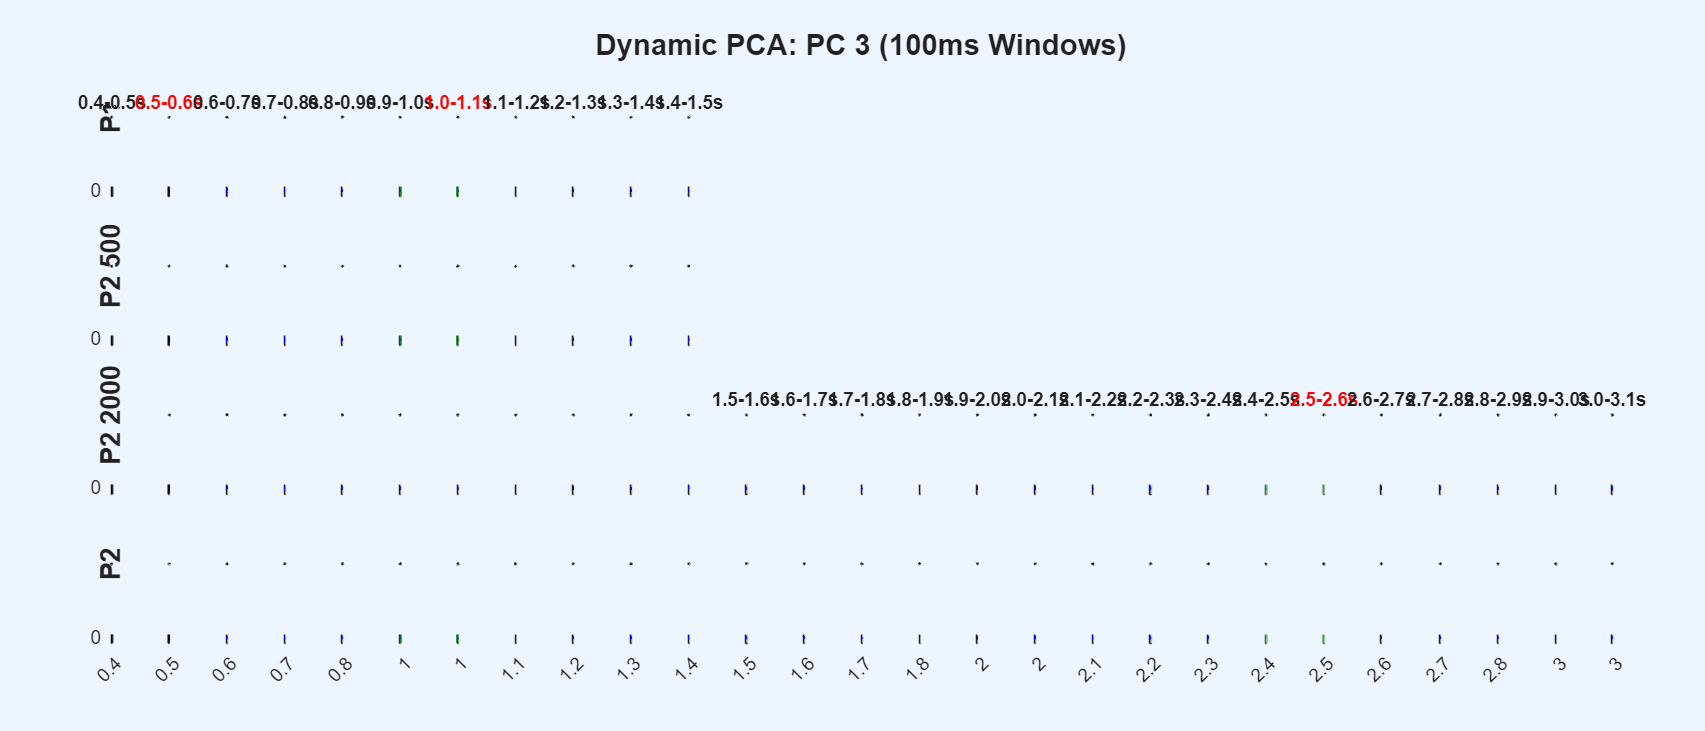

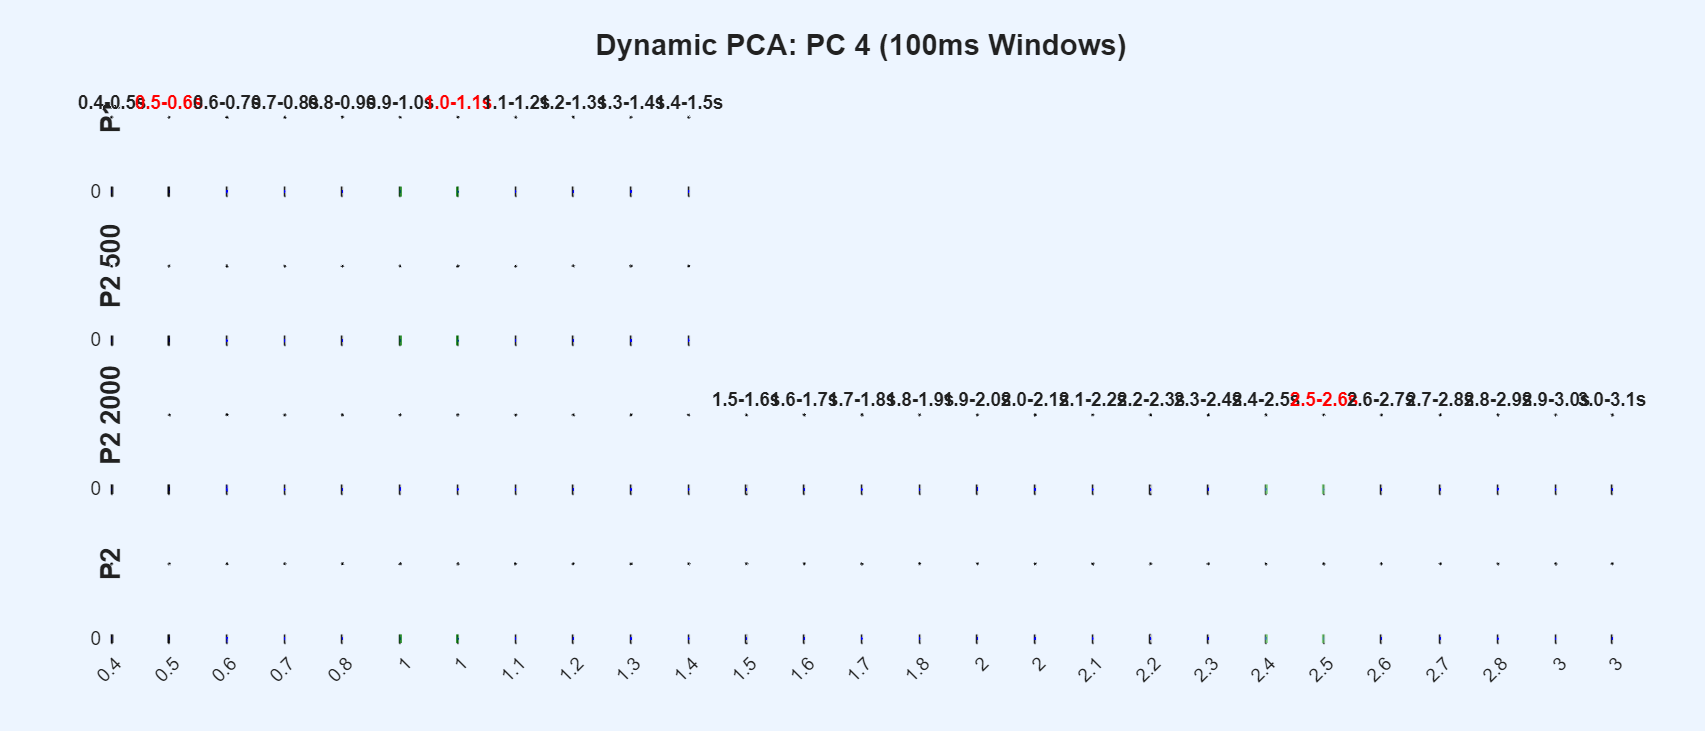

warning('off', 'all');

num_comps_plot = 4;
target_conds = {'P1', 'P2_500', 'P2_2000', 'P2'};
num_conds = length(target_conds);
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% 1. Define Fixed 100ms Plotting Windows spanning the full 0.4s to 3.1s range
plot_starts = 0.400 : 0.100 : 3.000; % [0.4, 0.5, 0.6 ... 3.0]
plot_ends   = 0.500 : 0.100 : 3.100; % [0.5, 0.6, 0.7 ... 3.1]
num_plot_windows = length(plot_starts);

for pc = 1:num_comps_plot
    fig_name = sprintf('Dynamic PCA: PC %d (100ms Windows)', pc);
    % Make figure very wide to accommodate 27 columns of 100ms chunks
    figure('Position', [50, 50, 2800, 1200], 'Name', fig_name);
    
    t = tiledlayout(num_conds * 2, num_plot_windows, 'TileSpacing', 'tight', 'Padding', 'compact');
    title(t, fig_name, 'FontSize', 22, 'FontWeight', 'bold');
    
    % --- CRITICAL: Calculate Global Y-Limits for this PC across ALL conditions ---
    min_val = inf; max_val = -inf;
    for cond_idx = 1:num_conds
        c_name = target_conds{cond_idx};
        
        % Explicitly define boundaries for these conditions
        if ismember(c_name, {'P1', 'P2_500'})
            valid_range = [0.4, 1.5];
        else
            valid_range = [0.4, 3.1];
        end
        
        for col = 1:num_plot_windows
             t_start = plot_starts(col);
             t_end = plot_ends(col);
             t_center = (t_start + t_end) / 2;
             
             if t_start < valid_range(1) - 0.001 || t_end > valid_range(2) + 0.001
                 continue;
             end
             
             [~, w_local] = min(abs(pca_dynamic.(c_name).time_vector - t_center));
             idx = find(time_ms_eeg >= t_start & time_ms_eeg < t_end);
             
             if ~isempty(idx)
                 X_win = data_grand_avg.(c_name)(:, idx);
                 mu = mean(X_win', 1);
                 trace = (X_win' - mu) * pca_dynamic.(c_name).coeffs(:, pc, w_local);
                 min_val = min(min_val, min(trace));
                 max_val = max(max_val, max(trace));
             end
        end
    end
    pad = (max_val - min_val) * 0.1;
    if pad == 0, pad = 1; end
    trace_limits = [min_val - pad, max_val + pad];
    
    % Generate the Plot Grid
    for cond_idx = 1:num_conds
        c_name = target_conds{cond_idx};
        clean_name = strrep(c_name, '_', ' ');
        
        if ismember(c_name, {'P1', 'P2_500'})
            valid_range = [0.4, 1.5];
        else
            valid_range = [0.4, 3.1];
        end
        
        % Global Color Scale for Topoplots for this condition
        max_topo = max(abs(pca_dynamic.(c_name).coeffs(:, pc, :)), [], 'all');
        clim_bound = [-max_topo, max_topo] * 0.8;
        if clim_bound(2) == 0, clim_bound = [-1 1]; end 
        
        for col = 1:num_plot_windows
            t_start = plot_starts(col);
            t_end   = plot_ends(col);
            t_center = (t_start + t_end) / 2;
            
            topo_tile_idx = (cond_idx - 1) * 2 * num_plot_windows + col;
            trace_tile_idx = ((cond_idx - 1) * 2 + 1) * num_plot_windows + col;
            
            % HARD BOUNDARY CHECK: Leave tiles blank if condition ends before this column
            if t_start < valid_range(1) - 0.001 || t_end > valid_range(2) + 0.001
                nexttile(topo_tile_idx); axis off;
                nexttile(trace_tile_idx); axis off;
                continue;
            end
            
            [~, w_local] = min(abs(pca_dynamic.(c_name).time_vector - t_center));
            
            % 1. Plot Topoplot
            nexttile(topo_tile_idx);
            spatial_weights = pca_dynamic.(c_name).coeffs(:, pc, w_local);
            topoplot(spatial_weights, EEG.chanlocs, 'electrodes', 'off', 'maplimits', clim_bound);
            
            % Add Headers (Top Row Only) with Red Highlights for appropriate Stimuli
            if cond_idx == 1 || (cond_idx == 3 && t_center > 1.5)
                if (0.5 >= t_start && 0.5 < t_end) || ...
                   (ismember(c_name, {'P1', 'P2_500', 'P2'}) && 1.0 >= t_start && 1.0 < t_end) || ...
                   (ismember(c_name, {'P2_2000', 'P2'}) && 2.5 >= t_start && 2.5 < t_end)
                    title(sprintf('%.1f-%.1fs', t_start, t_end), 'FontSize', 14, 'Color', 'r', 'FontWeight', 'bold');
                else
                    title(sprintf('%.1f-%.1fs', t_start, t_end), 'FontSize', 14, 'FontWeight', 'bold');
                end
            end
            
            % Condition Row Label (Leftmost active column)
            if col == 1
                text(-0.8, 0, clean_name, 'FontSize', 20, 'FontWeight', 'bold', 'Rotation', 90, 'HorizontalAlignment', 'center');
            end
            
            % 2. Plot Trace
            nexttile(trace_tile_idx);
            hold on;
            idx = find(time_ms_eeg >= t_start & time_ms_eeg < t_end);
            time_win = time_ms_eeg(idx);
            X_win = data_grand_avg.(c_name)(:, idx);
            mu = mean(X_win', 1);
            trace = (X_win' - mu) * pca_dynamic.(c_name).coeffs(:, pc, w_local);
            
            plot(time_win, trace, 'b', 'LineWidth', 2);
            
            % Event Lines
            if 0.5 >= t_start && 0.5 <= t_end
                xline(0.5, 'k--', 'LineWidth', 2);
            end
            if ismember(c_name, {'P1', 'P2_500', 'P2'}) && 1.0 >= t_start && 1.0 <= t_end
                xline(1.0, '--', 'Color', dark_green, 'LineWidth', 2);
            end
            if ismember(c_name, {'P2_2000', 'P2'}) && 2.5 >= t_start && 2.5 <= t_end
                xline(2.5, '--', 'Color', light_green, 'LineWidth', 2);
            end
            hold off;
            
            xlim([t_start, t_end]);
            ylim(trace_limits); 
            grid on;
            
            % Format Axes
            if cond_idx < num_conds && ~(cond_idx == 2 && col > 11) % P2_500 ends at col 11
                xticklabels({});
            else
                set(gca, 'FontSize', 14);
                xtickangle(45);
            end
            
            if col > 1
                yticklabels({});
            else
                set(gca, 'FontSize', 14);
                ylabel('Amp', 'FontSize', 16, 'FontWeight', 'bold');
            end
        end
    end
end

warning('on', 'all');

## 3.3 Matched Cosine Similarity (P1 vs P2)


disp('Calculating Matched Cosine Similarities (P2 Variations)...');

Calculating Matched Cosine Similarities (P2 Variations)...


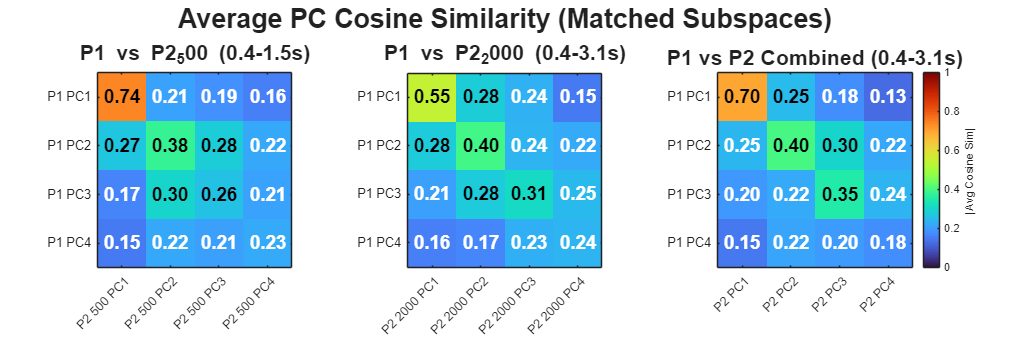


num_comps_sim = 4; 

sim_pairs = {
    {'P1', 'P2_500',  'P1 vs P2_500 (0.4-1.5s)', 0.4, 1.5},
    {'P1', 'P2_2000', 'P1 vs P2_2000 (0.4-3.1s)', 0.4, 3.1},
    {'P1', 'P2',      'P1 vs P2 Combined (0.4-3.1s)', 0.4, 3.1}
};

figure('Position', [100, 100, 1800, 600], 'Name', 'Matched Subspace Similarity');
t_avg = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t_avg, 'Average PC Cosine Similarity (Matched Subspaces)', 'FontSize', 20, 'FontWeight', 'bold');

for p = 1:length(sim_pairs)
    condA = sim_pairs{p}{1};
    condB = sim_pairs{p}{2};
    title_str = sim_pairs{p}{3};
    t_start = sim_pairs{p}{4};
    t_end = sim_pairs{p}{5};
    
    time_A = pca_dynamic.(condA).time_vector;
    time_B = pca_dynamic.(condB).time_vector;
    
    valid_A = find(time_A >= t_start - 0.001 & time_A <= t_end + 0.001);
    valid_B = find(time_B >= t_start - 0.001 & time_B <= t_end + 0.001);
    
    [shared_times, idx_A, idx_B] = intersect(time_A(valid_A), time_B(valid_B));
    final_idx_A = valid_A(idx_A);
    final_idx_B = valid_B(idx_B);
    num_shared_wins = length(shared_times);
    
    sim_mat_time = zeros(num_comps_sim, num_comps_sim, num_shared_wins);
    for w_idx = 1:num_shared_wins
        c_A = pca_dynamic.(condA).coeffs(:, 1:num_comps_sim, final_idx_A(w_idx));
        c_B = pca_dynamic.(condB).coeffs(:, 1:num_comps_sim, final_idx_B(w_idx));
        sim_mat_time(:, :, w_idx) = abs(c_A' * c_B);
    end
    
    mean_sim_mat = mean(sim_mat_time, 3);
    
    nexttile(t_avg);
    imagesc(mean_sim_mat); colormap('turbo'); caxis([0 1]); pbaspect([1 1 1]); 
    xticks(1:num_comps_sim); yticks(1:num_comps_sim);
    xticklabels(arrayfun(@(x) sprintf('%s PC%d', strrep(condB,'_',' '), x), 1:num_comps_sim, 'UniformOutput', false));
    yticklabels(arrayfun(@(x) sprintf('%s PC%d', strrep(condA,'_',' '), x), 1:num_comps_sim, 'UniformOutput', false));
    xtickangle(45);
    title(title_str, 'FontSize', 16, 'FontWeight', 'bold');
    
    for r = 1:num_comps_sim
        for c = 1:num_comps_sim
            val = mean_sim_mat(r,c);
            text_color = 'k'; if val < 0.25 || val > 0.8, text_color = 'w'; end
            text(c, r, sprintf('%.2f', val), 'HorizontalAlignment', 'center', 'Color', text_color, 'FontSize', 14, 'FontWeight', 'bold');
        end
    end
    if p == 3, cb = colorbar; cb.Label.String = '|Avg Cosine Sim|'; end
end

warning('on', 'all');

## 4.0 Plotting Individual Explained Variance (P1 vs P3 Variations)

%% 4.1 Plotting Individual Explained Variance (P3 Variations)
disp('Plotting Individual Explained Variance (P3 Variations)...');

Plotting Individual Explained Variance (P3 Variations)...


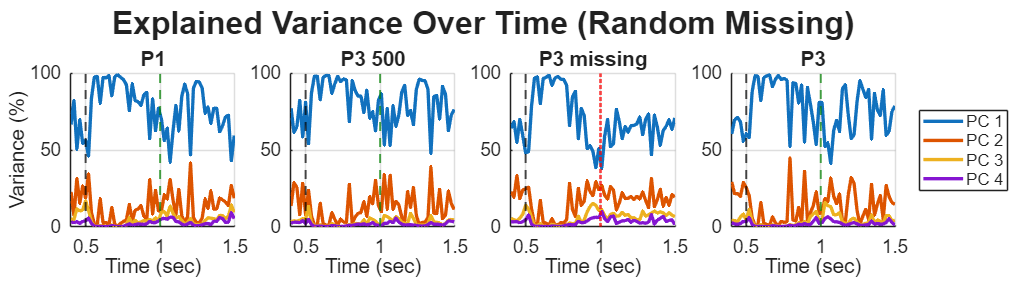


target_pca_conditions = {'P1', 'P3_500', 'P3_missing', 'P3'};

figure('Position', [50 50 1800 500], 'Name', 'Individual Variance Over Time');
t_var = tiledlayout(1, length(target_pca_conditions), 'TileSpacing', 'compact', 'Padding', 'compact');
title(t_var, 'Explained Variance Over Time (Random Missing)', 'FontSize', 24, 'FontWeight', 'bold');

for i = 1:length(target_pca_conditions)
    c_name = target_pca_conditions{i};
    nexttile;
    
    var_time = pca_dynamic.(c_name).exp_var;
    time_vec = pca_dynamic.(c_name).time_vector;
    
    hold on;
    colors = lines(num_comps); 
    for k = 1:num_comps
        plot(time_vec, var_time(k, :), 'Color', colors(k,:), 'LineWidth', 2.5, 'DisplayName', sprintf('PC %d', k));
    end
    
    xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Auditory Cue
    if ismember(c_name, {'P1', 'P3_500', 'P3'})
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Tactile Delivered
    elseif strcmp(c_name, 'P3_missing')
        xline(1.0, 'r:', 'LineWidth', 2.0, 'HandleVisibility', 'off'); % Tactile Missing
    end
    hold off;
    
    xlim([0.4, 1.5]);
    ylim([0 100]); 
    
    xlabel('Time (sec)');
    if i == 1, ylabel('Variance (%)'); end
    title(strrep(c_name, '_', ' '), 'FontSize', 18);
    grid on; set(gca,'FontSize',14);
    if i == length(target_pca_conditions), legend('Location', 'eastoutside'); end
end

## 4.1.b Plotting Group-Level Explained Variance (P3 Variations with Std Dev)

disp('Plotting Group-Level Explained Variance (P3 Variations)...');

Plotting Group-Level Explained Variance (P3 Variations)...


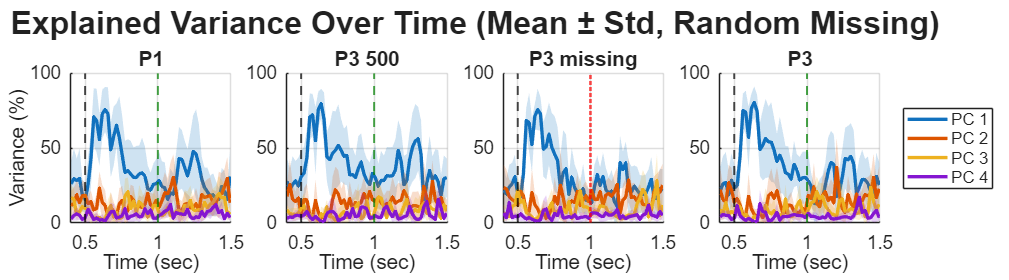


target_pca_conditions = {'P1', 'P3_500', 'P3_missing', 'P3'};

figure('Position', [50 50 1800 500], 'Name', 'Group Variance Over Time');
t_var = tiledlayout(1, length(target_pca_conditions), 'TileSpacing', 'compact', 'Padding', 'compact');
title(t_var, 'Explained Variance Over Time (Mean ± Std, Random Missing)', 'FontSize', 24, 'FontWeight', 'bold');

for i = 1:length(target_pca_conditions)
    c_name = target_pca_conditions{i};
    nexttile;
    
    % Extract the newly computed Mean and Std Dev matrices
    var_mu = stats_across_subjects.(c_name).var_mean;
    var_sd = stats_across_subjects.(c_name).var_std;
    time_vec = pca_dynamic.(c_name).time_vector;
    
    hold on;
    colors = lines(num_comps); 
    
    for k = 1:num_comps
        mu_k = var_mu(k, :);
        sd_k = var_sd(k, :);
        
        % 1. Create the Shaded Error Ribbon (patch)
        % THE FIX: using (:)' guarantees a flat row vector, and flip() works perfectly on it!
        x_patch = [time_vec(:)', flip(time_vec(:)')];
        y_patch = [mu_k(:)' + sd_k(:)', flip(mu_k(:)' - sd_k(:)')];
        
        patch(x_patch, y_patch, colors(k,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        
        % 2. Draw the solid Mean line on top
        plot(time_vec, mu_k, 'Color', colors(k,:), 'LineWidth', 2.5, 'DisplayName', sprintf('PC %d', k));
    end
    
    % Overlay stimulus markers
    xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Auditory Cue
    if ismember(c_name, {'P1', 'P3_500', 'P3'})
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Tactile Delivered
    elseif strcmp(c_name, 'P3_missing')
        xline(1.0, 'r:', 'LineWidth', 2.0, 'HandleVisibility', 'off'); % Tactile Missing
    end
    hold off;
    
    xlim([0.4, 1.5]);
    ylim([0 100]); 
    
    xlabel('Time (sec)');
    if i == 1, ylabel('Variance (%)'); end
    title(strrep(c_name, '_', ' '), 'FontSize', 18);
    grid on; set(gca,'FontSize',14);
    
    if i == length(target_pca_conditions)
        legend('Location', 'eastoutside'); 
    end
end

## 4.2 Event-Triggered Topoplots & Time Courses (P3 Variations)

%% 4.2 Visualizing Dynamic Topoplots & Time Courses (100ms Windows)
disp('Plotting Dynamic Topoplots and Time Courses (P3 Variations)...');

Plotting Dynamic Topoplots and Time Courses (P3 Variations)...


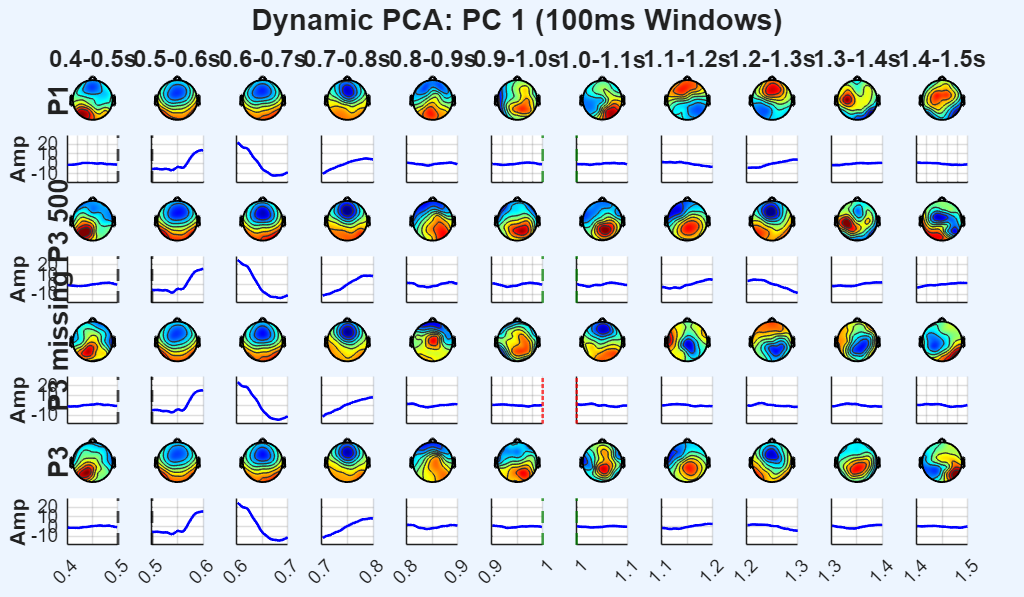

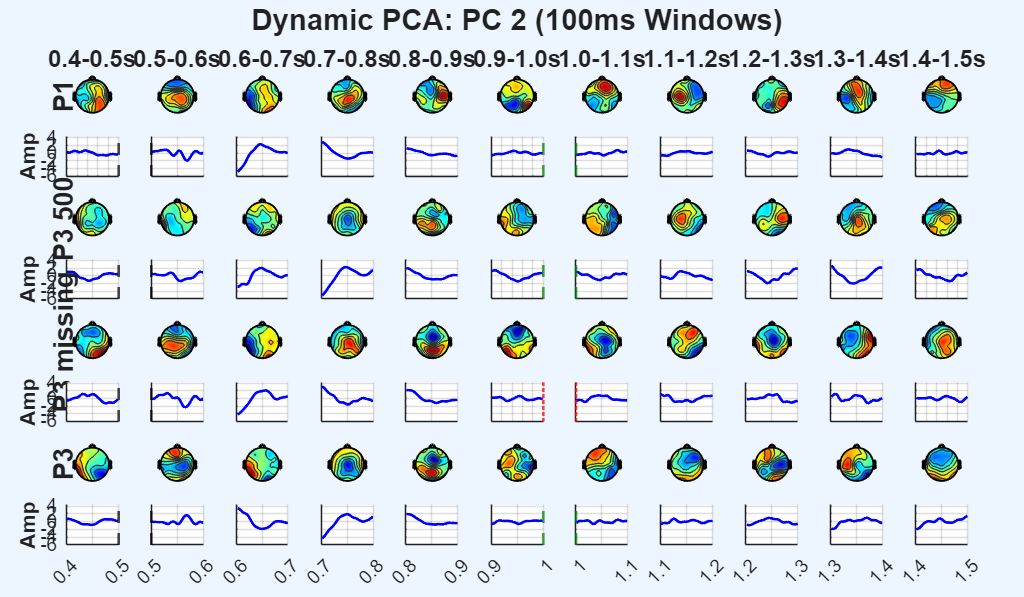

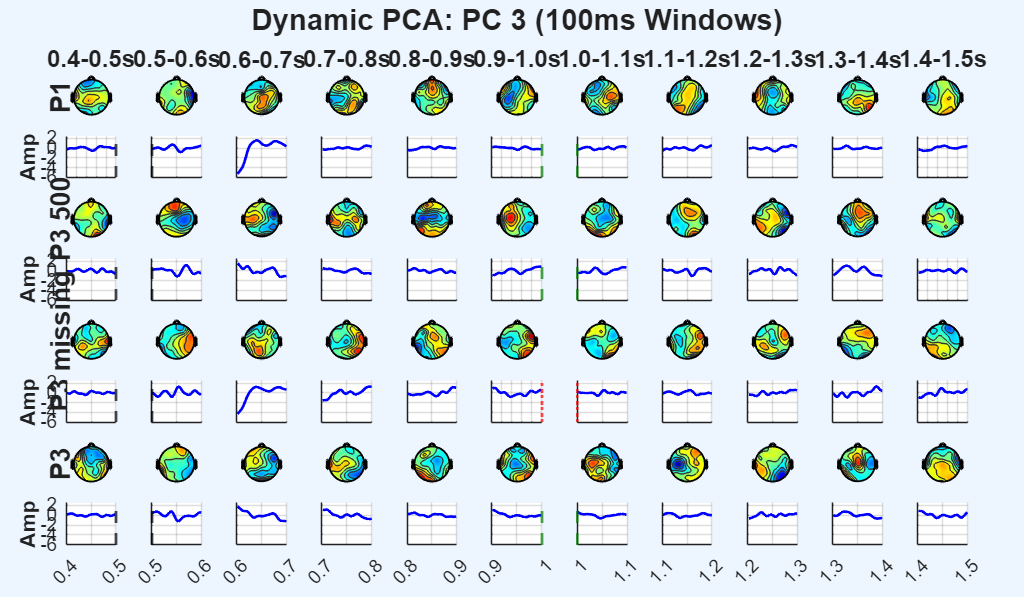

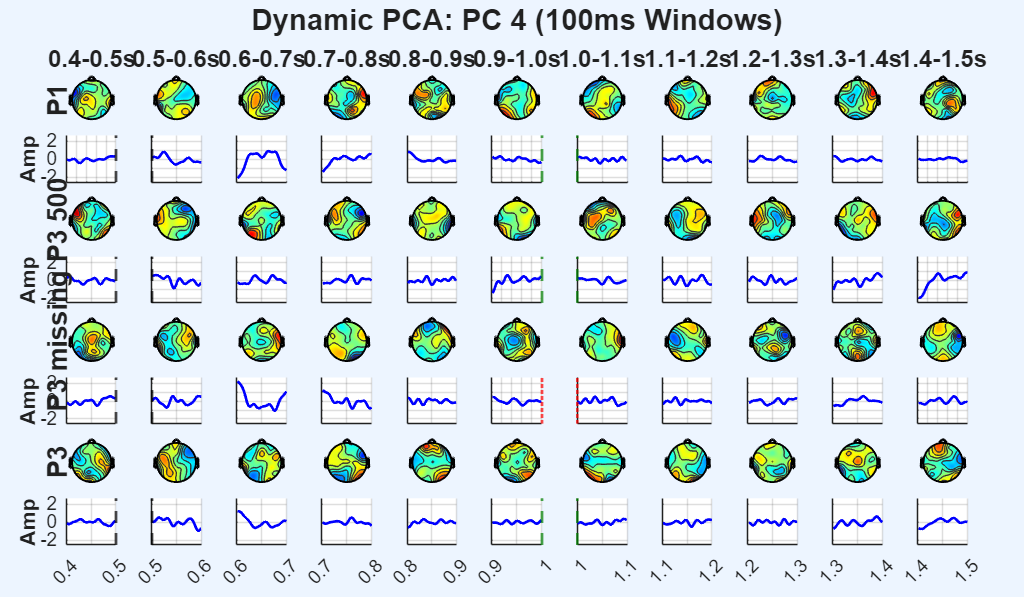

warning('off', 'all');

num_comps_plot = 4;
target_conds = {'P1', 'P3_500', 'P3_missing', 'P3'};
num_conds = length(target_conds);
dark_green  = [0 0.5 0];

% 1. Define Fixed 100ms Plotting Windows from 0.4s to 1.5s
plot_starts = 0.400 : 0.100 : 1.400; % [0.4, 0.5, 0.6 ... 1.4]
plot_ends   = 0.500 : 0.100 : 1.500; % [0.5, 0.6, 0.7 ... 1.5]
num_plot_windows = length(plot_starts);

for pc = 1:num_comps_plot
    fig_name = sprintf('Dynamic PCA: PC %d (100ms Windows)', pc);
    figure('Position', [50, 50, 2400, 1400], 'Name', fig_name);
    
    t = tiledlayout(num_conds * 2, num_plot_windows, 'TileSpacing', 'tight', 'Padding', 'compact');
    title(t, fig_name, 'FontSize', 22, 'FontWeight', 'bold');
    
    % --- CRITICAL: Calculate Global Y-Limits for this PC across ALL conditions ---
    min_val = inf; max_val = -inf;
    for cond_idx = 1:num_conds
        c_name = target_conds{cond_idx};
        valid_range = [0.4, 1.5]; % All P3 conditions fall strictly in this range
        
        for col = 1:num_plot_windows
             t_start = plot_starts(col);
             t_end = plot_ends(col);
             t_center = (t_start + t_end) / 2;
             
             if t_start < valid_range(1) - 0.001 || t_end > valid_range(2) + 0.001
                 continue;
             end
             
             [~, w_local] = min(abs(pca_dynamic.(c_name).time_vector - t_center));
             
             idx = find(time_ms_eeg >= t_start & time_ms_eeg < t_end);
             if ~isempty(idx)
                 X_win = data_grand_avg.(c_name)(:, idx);
                 mu = mean(X_win', 1);
                 trace = (X_win' - mu) * pca_dynamic.(c_name).coeffs(:, pc, w_local);
                 min_val = min(min_val, min(trace));
                 max_val = max(max_val, max(trace));
             end
        end
    end
    pad = (max_val - min_val) * 0.1;
    if pad == 0, pad = 1; end
    trace_limits = [min_val - pad, max_val + pad];
    
    % Generate the Plot Grid
    for cond_idx = 1:num_conds
        c_name = target_conds{cond_idx};
        clean_name = strrep(c_name, '_', ' ');
        valid_range = [0.4, 1.5];
        
        % Global Color Scale for Topoplots for this condition
        max_topo = max(abs(pca_dynamic.(c_name).coeffs(:, pc, :)), [], 'all');
        clim_bound = [-max_topo, max_topo] * 0.8;
        if clim_bound(2) == 0, clim_bound = [-1 1]; end 
        
        for col = 1:num_plot_windows
            t_start = plot_starts(col);
            t_end   = plot_ends(col);
            t_center = (t_start + t_end) / 2;
            
            topo_tile_idx = (cond_idx - 1) * 2 * num_plot_windows + col;
            trace_tile_idx = ((cond_idx - 1) * 2 + 1) * num_plot_windows + col;
            
            % Boundary check
            if t_start < valid_range(1) - 0.001 || t_end > valid_range(2) + 0.001
                nexttile(topo_tile_idx); axis off;
                nexttile(trace_tile_idx); axis off;
                continue;
            end
            
            [~, w_local] = min(abs(pca_dynamic.(c_name).time_vector - t_center));
            
            % 1. Plot Topoplot
            nexttile(topo_tile_idx);
            spatial_weights = pca_dynamic.(c_name).coeffs(:, pc, w_local);
            topoplot(spatial_weights, EEG.chanlocs, 'electrodes', 'off', 'maplimits', clim_bound);
            
            % Add Headers (Top Row Only - No "STIM" text, 18pt font)
            if cond_idx == 1 
                title(sprintf('%.1f-%.1fs', t_start, t_end), 'FontSize', 18, 'FontWeight', 'bold');
            end
            
            % Condition Row Label (Leftmost Column, 20pt font)
            if col == 1
                text(-0.8, 0, clean_name, 'FontSize', 20, 'FontWeight', 'bold', 'Rotation', 90, 'HorizontalAlignment', 'center');
            end
            
            % 2. Plot Trace
            nexttile(trace_tile_idx);
            hold on;
            idx = find(time_ms_eeg >= t_start & time_ms_eeg < t_end);
            time_win = time_ms_eeg(idx);
            X_win = data_grand_avg.(c_name)(:, idx);
            mu = mean(X_win', 1);
            trace = (X_win' - mu) * pca_dynamic.(c_name).coeffs(:, pc, w_local);
            
            plot(time_win, trace, 'b', 'LineWidth', 2);
            
            % Event Lines (Draw if the event falls inside this specific 100ms window)
            if 0.5 >= t_start && 0.5 <= t_end
                xline(0.5, 'k--', 'LineWidth', 2);
            end
            if ismember(c_name, {'P1', 'P3_500', 'P3'}) && 1.0 >= t_start && 1.0 <= t_end
                xline(1.0, '--', 'Color', dark_green, 'LineWidth', 2);
            end
            if strcmp(c_name, 'P3_missing') && 1.0 >= t_start && 1.0 <= t_end
                xline(1.0, 'r:', 'LineWidth', 2);
            end
            hold off;
            
            xlim([t_start, t_end]);
            ylim(trace_limits); % Unified limits applied here!
            grid on;
            
            % Format Axes to prevent clutter
            if cond_idx < num_conds
                xticklabels({});
            else
                set(gca, 'FontSize', 14);
                xtickangle(45);
            end
            
            if col > 1
                yticklabels({});
            else
                set(gca, 'FontSize', 14);
                ylabel('Amp', 'FontSize', 16, 'FontWeight', 'bold');
            end
        end
    end
end

warning('on', 'all');

## 4.3 Matched Cosine Similarity (P1 vs P3)

%% 4.3 Matched Cosine Similarity (P1 vs P3)
disp('Calculating Matched Cosine Similarities (P3 Variations)...');

Calculating Matched Cosine Similarities (P3 Variations)...


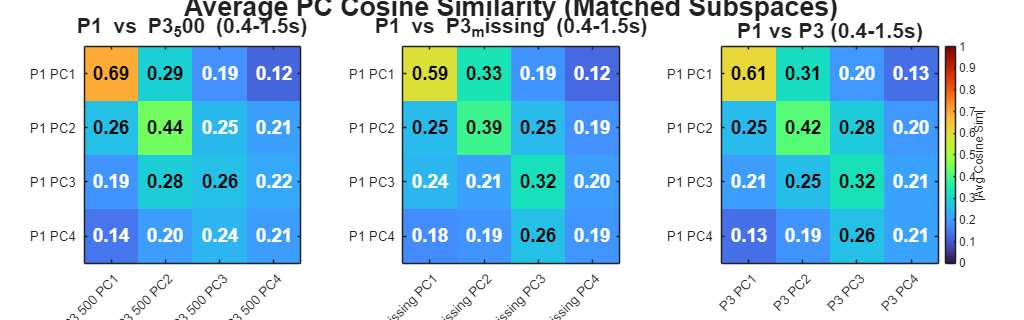


num_comps_sim = 4; 

sim_pairs = {
    {'P1', 'P3_500',     'P1 vs P3_500 (0.4-1.5s)', 0.4, 1.5},
    {'P1', 'P3_missing', 'P1 vs P3_missing (0.4-1.5s)', 0.4, 1.5},
    {'P1', 'P3',         'P1 vs P3 (0.4-1.5s)', 0.4, 1.5}
};

figure('Position', [100, 100, 1600, 500], 'Name', 'Matched Subspace Similarity');
t_avg = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t_avg, 'Average PC Cosine Similarity (Matched Subspaces)', 'FontSize', 20, 'FontWeight', 'bold');

for p = 1:length(sim_pairs)
    condA = sim_pairs{p}{1};
    condB = sim_pairs{p}{2};
    title_str = sim_pairs{p}{3};
    t_start = sim_pairs{p}{4};
    t_end = sim_pairs{p}{5};
    
    time_A = pca_dynamic.(condA).time_vector;
    time_B = pca_dynamic.(condB).time_vector;
    
    valid_A = find(time_A >= t_start - 0.001 & time_A <= t_end + 0.001);
    valid_B = find(time_B >= t_start - 0.001 & time_B <= t_end + 0.001);
    
    [shared_times, idx_A, idx_B] = intersect(time_A(valid_A), time_B(valid_B));
    final_idx_A = valid_A(idx_A);
    final_idx_B = valid_B(idx_B);
    num_shared_wins = length(shared_times);
    
    sim_mat_time = zeros(num_comps_sim, num_comps_sim, num_shared_wins);
    for w_idx = 1:num_shared_wins
        c_A = pca_dynamic.(condA).coeffs(:, 1:num_comps_sim, final_idx_A(w_idx));
        c_B = pca_dynamic.(condB).coeffs(:, 1:num_comps_sim, final_idx_B(w_idx));
        sim_mat_time(:, :, w_idx) = abs(c_A' * c_B);
    end
    
    mean_sim_mat = mean(sim_mat_time, 3);
    
    nexttile(t_avg);
    imagesc(mean_sim_mat); colormap('turbo'); caxis([0 1]); pbaspect([1 1 1]); 
    xticks(1:num_comps_sim); yticks(1:num_comps_sim);
    xticklabels(arrayfun(@(x) sprintf('%s PC%d', strrep(condB,'_',' '), x), 1:num_comps_sim, 'UniformOutput', false));
    yticklabels(arrayfun(@(x) sprintf('%s PC%d', strrep(condA,'_',' '), x), 1:num_comps_sim, 'UniformOutput', false));
    xtickangle(45);
    title(title_str, 'FontSize', 16, 'FontWeight', 'bold');
    
    for r = 1:num_comps_sim
        for c = 1:num_comps_sim
            val = mean_sim_mat(r,c);
            text_color = 'k'; if val < 0.25 || val > 0.8, text_color = 'w'; end
            text(c, r, sprintf('%.2f', val), 'HorizontalAlignment', 'center', 'Color', text_color, 'FontSize', 14, 'FontWeight', 'bold');
        end
    end
    if p == 3, cb = colorbar; cb.Label.String = '|Avg Cosine Sim|'; end
end